clc
clear all
pause('off')
close all

# 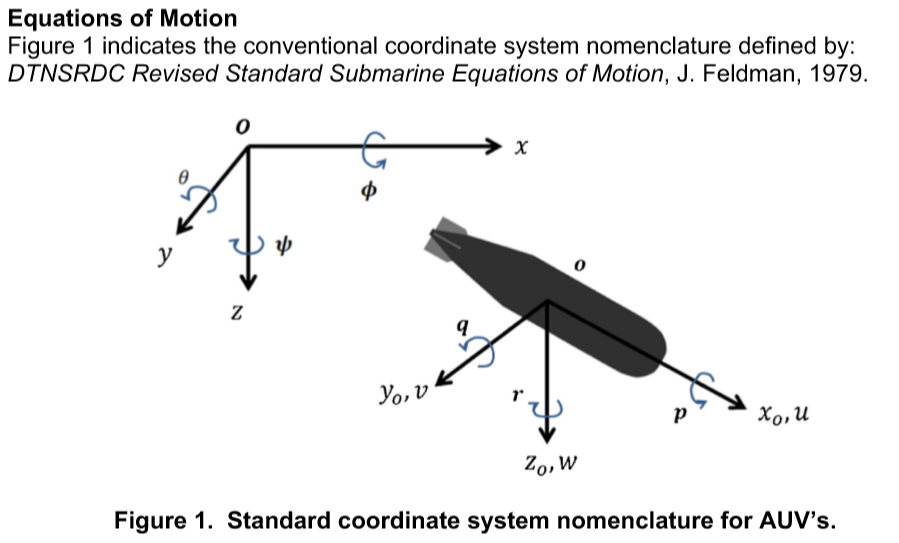

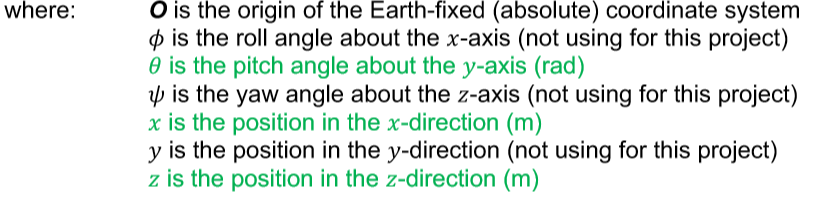

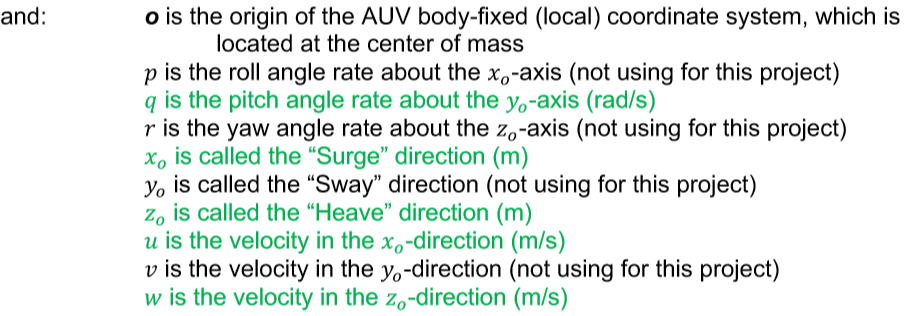

# Pitch Axis Model:

In the Pitch Axis/Driving Model/Vertical Axis Model, we are only interested in the variables that effect the vertical axis of the AUV.

**Equations of Motion:**

Relationship between world frame (*x, z, *$\theta \;${pitch angle about the y axis in radians }) and body frame (*u* {Velocity in the $x_0$ direction in $ms^{-1}$}, *w*  {Velocity in the $z_0$  direction}, *q* {pitch angle rate about the $y_0$ axis in $rad \cdot s^{-1}$}) coordinates.

Note: Our **State variables** are (**u, w, q, x, z, **$\theta$)

$\dot{x}(t) = u(t)
$       (1)        

$\dot{z}(t) = w(t)
$       (2)       

 $\dot{\theta}(t) = q(t)
$      (3)

Linearized dynamic equation relation with the linearized external forces and moments:


$$$\dot{u}(t) = \frac{- X_{u}u(t) + X_{T}(t)}{m + X_{\dot{u}} }  \ \ \ \ \ (4)$$$



$$$\dot{w}(t) = \frac{ - Z_{w}w(t) -Z_{\dot{q} }\dot{q}(t) - Z_{q}q(t) + Z_s(t) + Z_b(t) }{m +Z_{\dot{w}}}   \ \ \ \ \ (5)$   $$



$$ $\dot{q}(t) = \frac{ - M_{q}q(t) - M_{\dot w}{\dot w}(t) - M_{w}w(t) - x_{s}Z_s(t) + x_{b}Z_b(t) }{I_y + M_{\dot{q}}}   \ \ \ \ \ (6)$$$


Note: The outputs directly measured through sensors are: 

***x, z, ***$\theta$

# State Space Model(Matlab Computation):

We still need to solve the interconnected equations (5) and (6)

% Problem 1.

syms u_dot w_dot q_dot u w q X_u X_T X_udot m Z_w Z_wdot Z_q Z_qdot Z_s Z_b x_s x_b M_qdot M_wdot M_q M_w I_y x_dot z_dot theta_dot x z theta
State_Variable_Vector_dot = [u_dot; w_dot; q_dot; x_dot; z_dot; theta_dot];
State_Variable_Vector = [u; w; q; x; z; theta];
Input_Vector = [X_T; Z_s; Z_b];
Output_Vector = [x; z; theta];


% Coefficients of u_dot, w_dot, q_dot, x_dot, z_dot and theta_dot

A_1 = [                   0,                       0,                        0,      0,      0,      0;...
                          0,                        0,  (-Z_qdot)/(m + Z_wdot),      0,      0,      0;...
                          0,(-M_wdot)/(I_y + M_qdot),                        0,      0,      0,      0;...
                          0,                       0                         0,      0,      0,      0;...
                          0,                       0                         0,      0,      0,      0;...
                          0,                       0                         0,      0,      0,      0];


% Coefficients of u, w, q, x, z and theta             
A_2 = [   -X_u/(m + X_udot),                       0,                          0,       0,      0,      0;...
                          0,       -Z_w/(m + Z_wdot),          -Z_q/(m + Z_wdot),       0,      0,      0;...
                          0,     -M_w/(I_y + M_qdot),        -M_q/(I_y + M_qdot),       0,      0,      0;...
                          1,                       0,                          0,       0,      0,      0;...
                          0,                       1,                          0,       0,      0,      0;...
                          0,                       0,                          1,       0,      0,      0];
               
                          
% Coefficients of Inputs X_T, Z_s and Z_b
B_1 = [      1/(m + X_udot),                       0,                          0;...
                          0,          1/(m + Z_wdot),             1/(m + Z_wdot);...
                          0,   (-x_s)/(I_y + M_qdot),       (-x_b)/(I_y + M_qdot);...
                          0,                       0,                          0;...
                          0,                       0,                          0;...
                          0,                       0,                          0];

% Equation is set in this form:
%  State_Variable_Vector_dot = A_1 * State_Variable_Vector_dot + A_2 * State_Variable_Vector + B_1 * Input_Vector;
%  Output_Vector = C * State_Variable_Vector + D * Input_Vector;

% Check the computation
I = eye(6);
A = (I - A_1)\A_2; % Coefficients of u, w, q, x, z, and theta
B = (I - A_1)\B_1; % Coefficients of X_T, Z_s and Z_b
% C = eye(3);
C = [0,0,0,1,0,0;...
     0,0,0,0,1,0;...
     0,0,0,0,0,1];
D = zeros(3,3);

fprintf(' Matrix A for the State Space Model is: ');

 Matrix A for the State Space Model is: 

disp(A);

$$\begin{array}{l} \left(\begin{array}{cccccc} -\frac{X_{u}}{X_{\mathrm{udot}}+m} & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{I_{y}\,Z_{w}+\ddddot{M}\,Z_{w}-M_{w}\,\ddddot{Z}}{\sigma_{1}} & -\frac{I_{y}\,Z_{q}-M_{q}\,\ddddot{Z}+\ddddot{M}\,Z_{q}}{\sigma_{1}} & 0 & 0 & 0\\ 0 & -\frac{M_{w}\,Z_{\mathrm{wdot}}-M_{\mathrm{wdot}}\,Z_{w}+M_{w}\,m}{\sigma_{1}} & -\frac{M_{q}\,Z_{\mathrm{wdot}}-M_{\mathrm{wdot}}\,Z_{q}+M_{q}\,m}{\sigma_{1}} & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{y}\,Z_{\mathrm{wdot}}+\ddddot{M}\,Z_{\mathrm{wdot}}-M_{\mathrm{wdot}}\,\ddddot{Z}+I_{y}\,m+\ddddot{M}\,m \end{array}$$

fprintf('\n \n \n \n');


fprintf(' Matrix B for the State Space Model is: ');

 Matrix B for the State Space Model is: 

disp(B);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{1}{X_{\mathrm{udot}}+m} & 0 & 0\\ 0 & \frac{I_{y}+\ddddot{M}+\ddddot{Z}\,x_{s}}{\sigma_{1}} & \frac{I_{y}+\ddddot{M}+\ddddot{Z}\,x_{b}}{\sigma_{1}}\\ 0 & -\frac{M_{\mathrm{wdot}}+Z_{\mathrm{wdot}}\,x_{s}+m\,x_{s}}{\sigma_{1}} & -\frac{M_{\mathrm{wdot}}+Z_{\mathrm{wdot}}\,x_{b}+m\,x_{b}}{\sigma_{1}}\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{y}\,Z_{\mathrm{wdot}}+\ddddot{M}\,Z_{\mathrm{wdot}}-M_{\mathrm{wdot}}\,\ddddot{Z}+I_{y}\,m+\ddddot{M}\,m \end{array}$$

fprintf('\n \n \n \n');

# State Space Model (Setup with Variables)

Therefore, Your State Space Model with symbolic variables looks like:

$\left\lbrack \begin{array}{c}
\dot{u} \\
\dot{\;w} \\
\dot{\;q} \\
\dot{x} \\
\dot{\;z} \\
\dot{\;\theta } 
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{cccccc}
\frac{-X_u }{X_{\dot{u} } +m} & 0 & 0 & 0 & 0 & 0\\
0 & \frac{-\left(I_y Z_w +M_{\dot{q} } Z_w -M_w Z_{\dot{q} } \right)}{\sigma_1 } & \frac{-\left(I_y Z_q -M_q Z_{\dot{q} } +M_{\dot{q} } Z_q \right)}{\sigma_1 } & 0 & 0 & 0\\
0 & \frac{-\left(M_w Z_{\dot{w} } -\;M_{\dot{w} } Z_w \;+M_w m\right)}{\sigma_1 } & \frac{-\left(M_q Z_{\dot{w} } -\;M_{\dot{w} } Z_q \;+M_q m\right)}{\sigma_1 } & 0 & 0 & 0\\
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
q\\
x\\
z\\
\theta 
\end{array}\right\rbrack$ + $\left\lbrack \begin{array}{ccc}
\frac{1}{X_{\dot{u} } +m} & 0 & 0\\
0 & \frac{\left({I_y +\;M}_{\dot{q} } +Z_{\dot{q} } x_s \right)}{\sigma_1 } & \frac{\left({I_y +\;M}_{\dot{q} } +Z_{\dot{q} } x_b \right)}{\sigma_1 }\\
0 & \frac{-\left(M_{\dot{w} } +Z_{\dot{w} } x_s +mx_s \right)}{\sigma_1 } & \frac{\left(Z_{\dot{w} } x_b -M_{\dot{w} } +mx_b \right)}{\sigma_1 }\\
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$ $\left\lbrack \begin{array}{c}
X_T \\
Z_s \\
Z_b 
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{c}
x\\
z\\
\theta 
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
q\\
x\\
z\\
\theta 
\end{array}\right\rbrack$ + $\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
X_T \\
Z_s \\
Z_b 
\end{array}\right\rbrack$

where $\sigma_1 =I_y Z_{\dot{w} } +M_{\dot{q} } Z_{\dot{w} } -M_{\dot{w} } Z_{\dot{q} } +I_y m+M_{\dot{q} } m\;$

# Defining the Parameters

% Problem 2.

m= 500;                 % mass of the AUV (kg)
L = 25;                 % Length of vehicle (m)
I_y = (1/300)*m*(L^2);  % mass moment of inertia about the y_0 axis (kg•m^2)
X_udot = (1/30)*m;      % X_0 direction "added mass" from accelerating water (kg)
X_u = 94;               % X_0 direction hydrodynamic "drag" coefficient(N•s/m)
Z_wdot = (1/10)*m;      % Z_0 direction "added mass" from accelerating water (kg)
Z_w = 470;              % Z_0 direction hydrodynamic "drag" coefficient (N•s/m), 4.7e2 = 4.7*(10^2)
Z_qdot = (1/20)*m;      % Z_0 direction "added mass" caused by rotation (kg•m)
Z_q = 950;              % Z_0 direction hydrodynamic drag caused by rotation (kg•m/s), 9.5e2 = 9.5*(10^2)
M_qdot = (1/20)*I_y;    % "added rotational inertia about the Y_0 axis (kg•m^2)
M_q = 1100;             % moment"drag" coefficient about the Y_0 axis (N•m•s), 1.1e3 = 1.1*(10^3)
M_wdot = (1/40)*I_y;    % "added rotational inertia" about the Y_0 axis (kg•m)
M_w = 320;              % moment "drag" coefficient about the Y_0 axis (N•s)
x_s = -(1/3)*L;         % position of the stern(rear)control surface in the X_0 direction (m)
x_b = (1/3)*L;          % position of the bow (front)control surface in the X_0 direction (m)
U_max = 3000000;        % Max Control Input, 3e6 = 3*(10^6)

# State Space Model(Numeric Matrices)

% Problem 3.

currentPrecision = digits;
digitsOld = digits(3); % Changing the precision for the no of places upto which I want the solution 

% subs used to find the solution after substituting numeric values to the
% symbolic varaibles
% double used to convert from symbolic array to numeric array, in order to use it in further computations
A_Numeric = double(vpa(subs(A))); 
B_Numeric = double(vpa(subs(B)));

fprintf(' Matrix A for the State Space Model is: ');

 Matrix A for the State Space Model is: 

disp(A_Numeric);

   -0.1820         0         0         0         0         0
         0   -0.8420   -1.6800         0         0         0
         0   -0.2730   -0.9660         0         0         0
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0



fprintf('\n \n \n \n');


fprintf(' Matrix B for the State Space Model is: ');

 Matrix B for the State Space Model is: 

disp(B_Numeric);

    0.0019         0         0
         0    0.0015    0.0022
         0    0.0076   -0.0077
         0         0         0
         0         0         0
         0         0         0



fprintf('\n \n \n \n');


fprintf(' Matrix C for the State Space Model is: ');

 Matrix C for the State Space Model is: 

disp(C);

     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



fprintf('\n \n \n \n');


fprintf(' Matrix D for the State Space Model is: ');

 Matrix D for the State Space Model is: 

disp(D);

     0     0     0
     0     0     0
     0     0     0



fprintf('\n \n \n \n');


% My LTI object
ol_sys = ss(A_Numeric, B_Numeric, C, D);

% Giving a descriptive name to states, inputs, and outputs
set(ol_sys, 'StateName', {'Surge (u)'; 'Heave (w)'; 'Pitch Angle Rate (q)'; 'Position in the x direction (x)'; 'Position in the z direction i.e. Depth (z)'; 'Pitch Angle about y-axis (theta)'},...
'StateUnit', {'m/s'; 'm/s'; 'rad/s'; 'm'; 'm'; 'rad'},...
            'InputName', {'Thrust in x_0 direction (X_T)'; 'Stern Thrust in z_0 direction (Z_s)'; 'Bow Thrust  in z_0 direction (Z_b)'},...
            'InputUnit', {'N'; 'N'; 'N'},...    
            'OutputName', {'Position in the x direction (x)'; 'Position in the z direction i.e. Depth (z)'; 'Pitch Angle about y-axis (theta)'},...
            'OutputUnit', {'m'; 'm'; 'rad'});
disp('My LTI object is: ');

My LTI object is: 


save Midterm_OL_SS_LTI_Model ol_sys
disp(ol_sys);

  3×3 ss array with properties:

                A: [6×6 double]
                B: [6×3 double]
                C: [3×6 double]
                D: [3×3 double]
                E: []
           Scaled: 0
        StateName: {6×1 cell}
        StateUnit: {6×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [3×1 double]
      OutputDelay: [3×1 double]
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {3×1 cell}
        InputUnit: {3×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]



fprintf('\n \n \n \n');

Therefore, Your State Space Model with numeric A,B,C and D looks like:

$\left\lbrack \begin{array}{c}
\dot{u} \\
\dot{\;w} \\
\dot{\;q} \\
\dot{x} \\
\dot{\;z} \\
\dot{\;\theta } 
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{cccccc}
-0\ldotp 1819 & 0 & 0 & 0 & 0 & 0\\
0 & -0\ldotp 8422 & -1\ldotp 6830 & 0 & 0 & 0\\
0 & -0\ldotp 2725 & -0\ldotp 9656 & 0 & 0 & 0\\
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
q\\
x\\
z\\
\theta 
\end{array}\right\rbrack$ + $\left\lbrack \begin{array}{ccc}
0\ldotp 0019 & 0 & 0\\
0 & 0\ldotp 0015 & 0\ldotp 0022\\
0 & 0\ldotp 0076 & -0\ldotp 0077\\
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$ $\left\lbrack \begin{array}{c}
X_T \\
Z_s \\
Z_b 
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{c}
x\\
z\\
\theta 
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
q\\
x\\
z\\
\theta 
\end{array}\right\rbrack$ + $\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
X_T \\
Z_s \\
Z_b 
\end{array}\right\rbrack$

# Minimum Realization

% Problem 4

cloopmin = minreal(ol_sys);
disp(' The minimum realization of our LTI object is: ');

 The minimum realization of our LTI object is: 


disp(cloopmin);

  3×3 ss array with properties:

                A: [6×6 double]
                B: [6×3 double]
                C: [3×6 double]
                D: [3×3 double]
                E: []
           Scaled: 0
        StateName: {6×1 cell}
        StateUnit: {6×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [3×1 double]
      OutputDelay: [3×1 double]
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {3×1 cell}
        InputUnit: {3×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]



fprintf('\n \n \n \n');


% if and isequal statements to check if the State Space Model is the
% minimum realization
if(isequal(cloopmin.A,A_Numeric) && isequal(cloopmin.B,B_Numeric)...
        && isequal(cloopmin.C,C) && isequal(cloopmin.D,D))
    disp(' Our State Space Model is the minimum realization ');
    fprintf('\n \n \n \n');
else
    disp(' Our State Space Model is Not the minimum realization ');
    fprintf('\n \n \n \n');
end

 Our State Space Model is the minimum realization 


# Controllability

If the rank of the controllability matrix is equal to the maximum possible rank, then the system is **controllable**.

**For example**: If we have a controllability matrix K, that has a rank N, where N is the number of columns of A matrix of size NxN, and matrix K is defined as $K=\left\lbrack B,\mathrm{AB},A^2 B,A^3 B,\ldotp \ldotp \ldotp \ldotp A^{N-1} B\right\rbrack$

In our Case, N = 6, and thus K martrix is full rank iff rank(K) = 6

**Note**: We also need to check which components of the Input Matrix feeding into the controllable system after being multiplied by Matrix B_Numeric have an impact on the controllability of the system.

We notice that the **Input_Vector(2)** and  **Input_Vector(3)** after being multiplied by Matrix B_Numeric still have an impact on the controllability of the system

% Problem 5.

K_Controllability = ctrb(A_Numeric,B_Numeric);
Rank_K_Controllability = rank(K_Controllability);

disp(' The rank of the controllability matrix is: ');

 The rank of the controllability matrix is: 


disp(Rank_K_Controllability);

     6



if Rank_K_Controllability == 6
    disp(' Thus, the LTI system is completely controllable ');
end

 Thus, the LTI system is completely controllable 



B_without_Input_2 = B_Numeric;
B_without_Input_2(:,2) = zeros(6,1);
K_Controllability_without_Input_2 = ctrb(A_Numeric,B_without_Input_2);
Rank_K_Controllability_without_Input_2 = rank(K_Controllability_without_Input_2);
disp(' The rank of the controllability matrix without Input_Vector(2) is: ');

 The rank of the controllability matrix without Input_Vector(2) is: 


disp(Rank_K_Controllability_without_Input_2);

     5




B_without_Input_3 = B_Numeric;
B_without_Input_3(:,3) = zeros(6,1);
K_Controllability_without_Input_3 = ctrb(A_Numeric,B_without_Input_3);
Rank_K_Controllability_without_Input_3 = rank(K_Controllability_without_Input_3);
disp(' The rank of the controllability matrix without Input_Vector(3) is: ');

 The rank of the controllability matrix without Input_Vector(3) is: 


disp(Rank_K_Controllability_without_Input_3);

     5




B_without_Input_2_3 = B_Numeric;
B_without_Input_2_3(:,2:3) = zeros(6,2);
K_Controllability_without_Input_2_3 = ctrb(A_Numeric,B_without_Input_2_3);
Rank_K_Controllability_without_Input_2_3 = rank(K_Controllability_without_Input_2_3);
disp(' The rank of the controllability matrix without Input_Vector(2) and Input_Vector(3) is: ');

 The rank of the controllability matrix without Input_Vector(2) and Input_Vector(3) is: 


disp(Rank_K_Controllability_without_Input_2_3);

     2



# Natural Frequency, Damping Ratio, and Poles of Continuous-Time System

**Note**: The "damp" function returns the poles in the order of increasing natural frequency !!

% Problem 6.

eigen_values = eig(A_Numeric);
disp(' The Eigen values are: ');

 The Eigen values are: 


disp(eigen_values);

         0
         0
   -1.5841
   -0.2239
         0
   -0.1820



fprintf('\n \n \n \n');


% Note: Damp prints poles in order of increasing natural frequency !!
disp(' The Natural Frequency (wn), Damping Ratio(zeta) and Open-loop poles(p) of our State Space Model are: ');

 The Natural Frequency (wn), Damping Ratio(zeta) and Open-loop poles(p) of our State Space Model are: 


[wn,zeta,p] = damp(ol_sys);
damp(ol_sys)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.82e-01     1.00e+00       1.82e-01         5.49e+00    
 -2.24e-01     1.00e+00       2.24e-01         4.47e+00    
 -1.58e+00     1.00e+00       1.58e+00         6.31e-01    


wn = wn/(2*pi);

T = table(wn, zeta, p);
T.Properties.VariableNames = {'Natural_Frequency_Wn_in_Hertz','Damping_Ratio_zeta','Poles_p'};
disp(T);

    Natural_Frequency_Wn_in_Hertz    Damping_Ratio_zeta    Poles_p 
    _____________________________    __________________    ________

                     0                       -1                   0
                     0                       -1                   0
                     0                       -1                   0
              0.028966                        1              -0.182
              0.035641                        1            -0.22394
               0.25211                        1             -1.5841



fprintf('\n \n \n \n');

# Initial Value Response

**Translation of Coordinate System**

**Note**: We need to do the translation of our coordinate system since the damp function damps the final coordinate of our system to the origin. We want the AUV to move to a certain coordinate which is x = 470 m and z = 150 m. Therefore, we need to translate our initial condition for x and z based on our new  origin for x and z values, whereas before it was found for for x = 0 and z = 0

% Problem 7.

% Initial condition for output responses
% Translation of Origin for x and z from (0,0) to (470,150) also changes
% initial values for x and z
x_0 = -470 + 50;           % meters
z_0 = -150 + 350;          % meters
theta_0 = (45*pi/180);     % 45 degrees = (45*pi/180) radians

% Initial condition for State Variables
u_0 = 100;          % m/s
w_0 = -300;         % m/s
q_0 = 0;            % rad/s

State_Variable_Vector_0 = [u_0; w_0; q_0; x_0; z_0; theta_0];

% Simulate unforced system with initial conditions
% Here your Y is the outputs (x, z, theta) and X is the state response
% (u, w, q, x, z, theta)
[Y,T,X] = initial(ol_sys,State_Variable_Vector_0);

% We need to cut those x and z values back for final plot
Y(:,1) = Y(:,1) + 470;
Y(:,2) = Y(:,2) + 150;

% Converting the theta angle from degrees to radians
Y(:,3) = (Y(:,3)*pi/180);
X(:,6) = (X(:,6)*pi/180);

% Since default settling time of LSIMINFO is 2%, for our problem we need to
% change it to 5% for both state responses (X) and the output Responses (Y)
S_States = lsiminfo(X,T,'SettlingTimeThreshold',0.05);
S_Only_Output = lsiminfo(Y,T,'SettlingTimeThreshold',0.05);

% Since the State responses contain states which are also my output
% response !! I am trying to keep it simple by just using the State
% Responses
% Converting LSIMINFO structure to a table for display purposes
STable = struct2table(S_States); 

% Display 5% Settling time for each open-loop output response
disp(' 5% Settling Time of open-loop response for Surge(u) is: ');

 5% Settling Time of open-loop response for Surge(u) is: 


disp(STable.SettlingTime(1));

   16.3901



disp(' 5% Settling Time of open-loop response for Heave(w) is: ');

 5% Settling Time of open-loop response for Heave(w) is: 


disp(STable.SettlingTime(2));

   10.6661



disp(' 5% Settling Time of open-loop response for Pitch Angle Rate(q) is: ');

 5% Settling Time of open-loop response for Pitch Angle Rate(q) is: 


disp(STable.SettlingTime(3));

   15.4797



disp(' 5% Settling Time of open-loop response for Position in x-direction(x) is: ');

 5% Settling Time of open-loop response for Position in x-direction(x) is: 


disp(STable.SettlingTime(4));

   16.3901



disp(' 5% Settling Time of open-loop response for Depth(z) is: ');

 5% Settling Time of open-loop response for Depth(z) is: 


disp(STable.SettlingTime(5));

   12.8710



disp(' 5% Settling Time of open-loop response for Pitch Angle(theta) is: ');

 5% Settling Time of open-loop response for Pitch Angle(theta) is: 


disp(STable.SettlingTime(6));

   14.0458





% Since I have values of Surge outputs at
% T(283) = 16.3980464506444 sec and T(284) = 16.4561955515333 sec 
% Therefore, I need to interpolate to find the exact value of surge at the
% 5% settling time

% Surge (u) at 5% Settling time, 
Surge_at_SettlingTime = interp1(T(:,1),X(:,1),STable.SettlingTime(1));
disp(' Surge (u) at 5% Settling time: ');

 Surge (u) at 5% Settling time: 


fprintf('Time = %.4f s, Surge(u) = %.4f m/s', STable.SettlingTime(1), Surge_at_SettlingTime);

Time = 16.3901 s, Surge(u) = 5.0641 m/s


% Heave (w) at 5% Settling time, 
Heave_at_SettlingTime = interp1(T(:,1),X(:,2),STable.SettlingTime(2));
disp(' Heave (w) at 5% Settling time: ');

 Heave (w) at 5% Settling time: 


fprintf('Time = %.4f s, Heave(w) = %.4f m/s', STable.SettlingTime(2), Heave_at_SettlingTime);

Time = 10.6661 s, Heave(w) = -15.0195 m/s


% Pitch Angle Rate (q) at 5% Settling time, 
PitchAngleRate_at_SettlingTime = interp1(T(:,1),X(:,3),STable.SettlingTime(3));
disp(' Pitch Angle Rate (q) at 5% Settling time: ');

 Pitch Angle Rate (q) at 5% Settling time: 


fprintf('Time = %.4f s, Pitch_Angle_Rate(q) = %.4f rad/s', STable.SettlingTime(3), PitchAngleRate_at_SettlingTime);

Time = 15.4797 s, Pitch_Angle_Rate(q) = 1.8803 rad/s


% Position in X (x) at 5% Settling time, 
X_at_SettlingTime = interp1(T(:,1),Y(:,1),STable.SettlingTime(4));
disp(' Position in X (x) at 5% Settling time: ');

 Position in X (x) at 5% Settling time: 


fprintf('Time = %.4f s, Position in X (x) = %.4f m', STable.SettlingTime(4), X_at_SettlingTime);

Time = 16.3901 s, Position in X (x) = 571.6260 m


% Depth(z) at 5% Settling time, 
Depth_at_SettlingTime = interp1(T(:,1),Y(:,2),STable.SettlingTime(5));
disp(' Depth(z) at 5% Settling time: ');

 Depth(z) at 5% Settling time: 


fprintf('Time = %.4f s, Depth(z) = %.4f m', STable.SettlingTime(5), Depth_at_SettlingTime);

Time = 12.8710 s, Depth(z) = -426.0200 m


% Pitch Angle (theta) at 5% Settling time, 
PitchAngle_at_SettlingTime = interp1(T(:,1),Y(:,3),STable.SettlingTime(6));
disp(' Pitch Angle (theta) at 5% Settling time: ');

 Pitch Angle (theta) at 5% Settling time: 


fprintf('Time = %.4f s, Pitch_Angle(theta) = %.4f rad', STable.SettlingTime(6), PitchAngle_at_SettlingTime);

Time = 14.0458 s, Pitch_Angle(theta) = 3.8413 rad

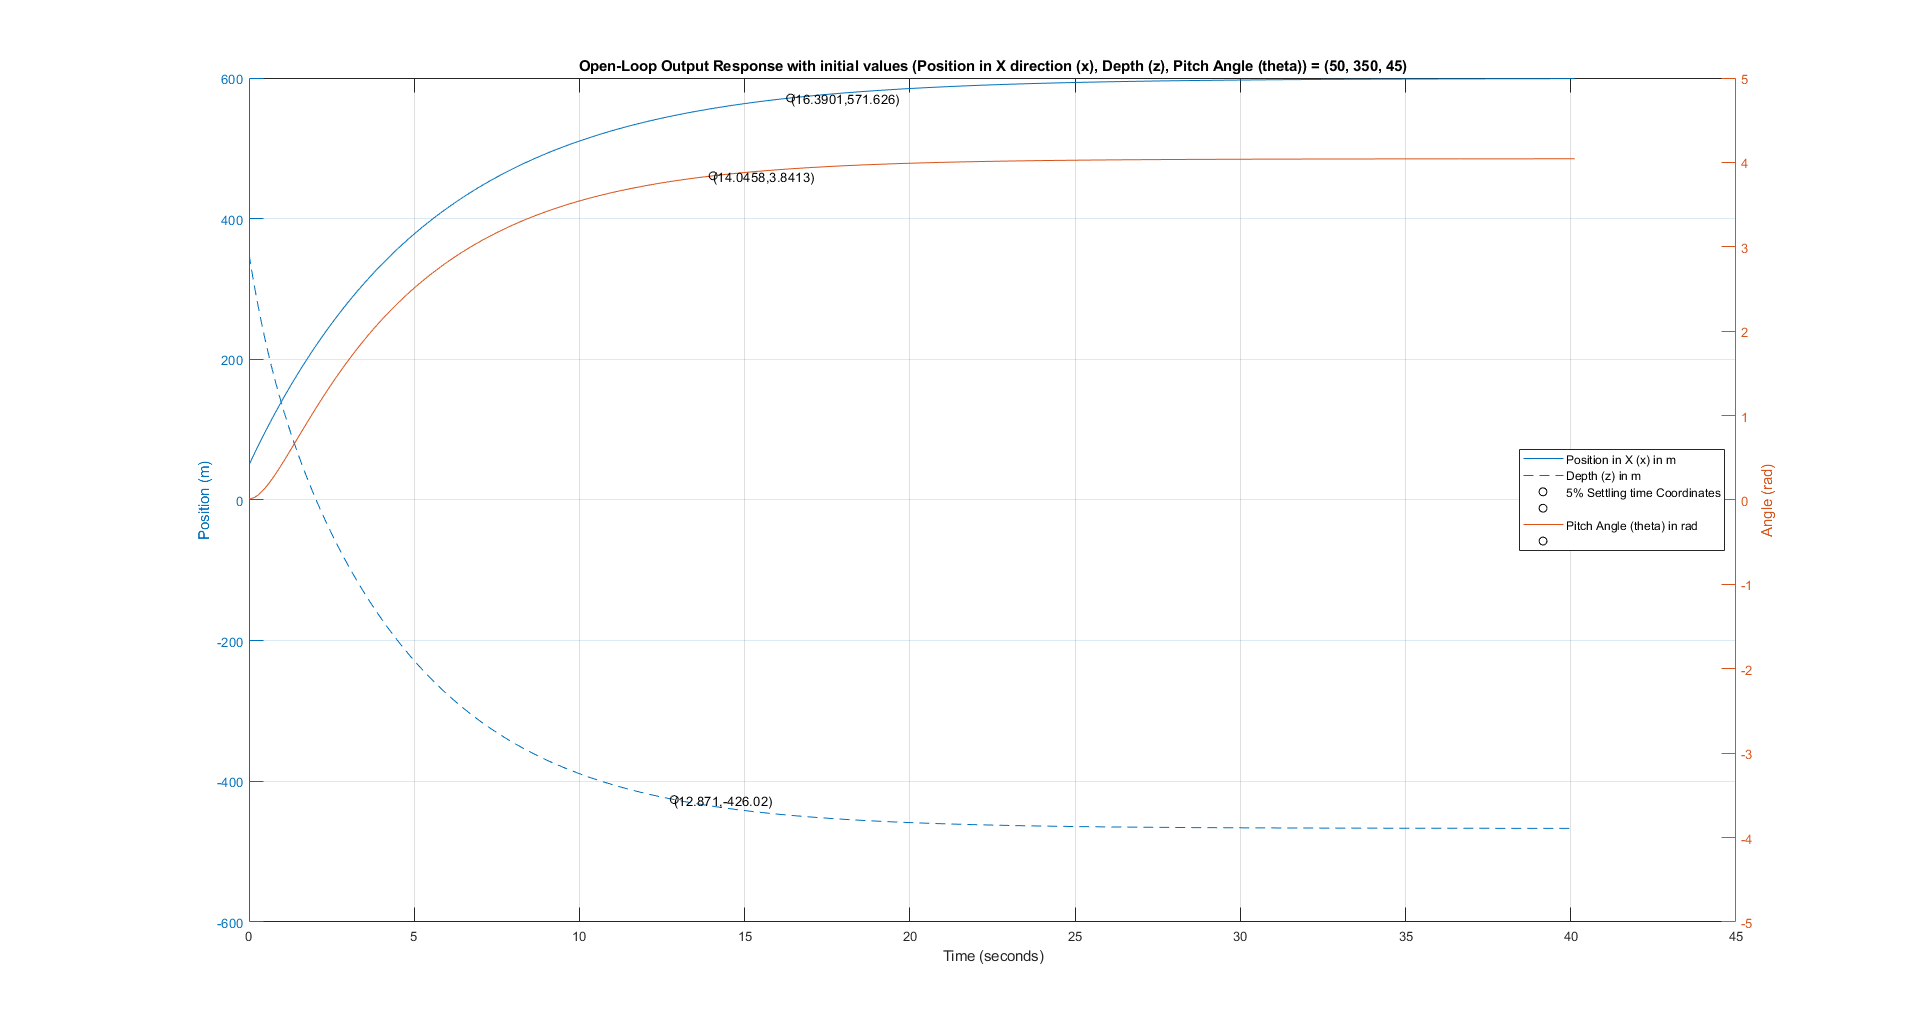

      
figure()
% Construct the left Y-axes for unit m/s
yyaxis left
plot(T,Y(:,1));
grid on
hold on
plot(T,Y(:,2));
title(['Open-Loop Output Response with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Position (m)')
ylim([-600 600]);
plot(STable.SettlingTime(4), X_at_SettlingTime,'kO');
text(STable.SettlingTime(4), X_at_SettlingTime,['(' num2str(STable.SettlingTime(4)) ',' num2str(X_at_SettlingTime) ')']);

plot(STable.SettlingTime(5), Depth_at_SettlingTime,'kO');
text(STable.SettlingTime(5), Depth_at_SettlingTime,['(' num2str(STable.SettlingTime(5)) ',' num2str(Depth_at_SettlingTime) ')']);


% Construct the right Y-axes for unit rad/s
yyaxis right
plot(T,Y(:,3));
ylim([-5 5]);

% Marking points of 5% Settling Time, and displaying the coordinates on the
% plot

plot(STable.SettlingTime(6), PitchAngle_at_SettlingTime,'kO');
text(STable.SettlingTime(6), PitchAngle_at_SettlingTime,['(' num2str(STable.SettlingTime(6)) ',' num2str(PitchAngle_at_SettlingTime) ')']);
ylabel('Angle (rad)');
h = legend('Position in X (x) in m', 'Depth (z) in m', '5% Settling time Coordinates', '' , 'Pitch Angle (theta) in rad', '');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Setting Position of Legend on the Bottom right (southeast)
set(h, 'Location','east');
hold off

# Full-State Feedback Controller

## **Performance requirements:**

- $\left|X_T \right|\le U_{\mathrm{max}\;}$          where   $U_{\mathrm{max}\;}$ = 3000000 N or 3e6 N

- 
$$\left|Z_s \right|\le U_{\mathrm{max}\;}$$


- 
$$\left|Z_b \right|\le U_{\mathrm{max}\;}$$


- AUV must completely enter the tunnel without contacting the barrier

- Minimize the time it takes to enter the tunnel

## Documentations includes:

- Choice of desired closed-loop poles

- Indication of whether I meet the requirements for entering the tunnel without contact

- An Indication of whether I meet the requirements for control signal saturation

- 5% Settling times for each of the putputs

From the given simulation I can see that the simulation lasts for 2.5 seconds, Therefore, my 5% settling time needs to be less than 2.5 seconds

We know, for 5% Settling Time:

$T_S =-\frac{\mathrm{ln}\left(0\ldotp 05\right)}{\zeta \omega_n }$,         

According to our Simulation, $T_S$ < 2.5 seconds

Therefore, $\zeta \omega_n$ $<=-\frac{\mathrm{ln}\left(0\ldotp 05\right)}{2\ldotp 5}$     $\Longrightarrow \;$$\zeta \omega_n$ $<=-1\ldotp 198$

Therefore, each eigenvalue must have a real part < -1.198,  which defines the envelope convergence.

Now, we just need to place our desired poles and form a closed loop controller that satisfies K*$X_i \left(t\right)<3\mathrm{e6}\;\mathrm{for}\;\mathrm{all}\;i\;\mathrm{and}\;t$

**Note**: My states are in order of $\dot{x}$,$\dot{z}$, $\theta^˙$, x, z, $\theta$ ! So in order to make appropriate changes to an output response, we can change pole relative to that order in our Pole vector.

Note: The poles closer to the imaginary axis are the dominant poles.

## **Trial 1**

% Problem 8. Trial 1

% We start off by setting each desired pole location to some lambda < -1.198:

P1 = [-1.2; -3; -2;-1.2; -3; -2]; % desired CL pole locations
K1 = place(A_Numeric, B_Numeric, P1); % proportional gains
A_closed1 = A_Numeric - B_Numeric*K1; % equivalent open-loop A for the closed-loop system
ss_closed1 = ss(A_closed1, B_Numeric, C, D); % still where equivalent U = 0.
[Y1,t1,X1] = initial(ss_closed1, State_Variable_Vector_0);

% Do not forget to return the coordinate system back to normal
Y1(:,1) = Y1(:,1) + 470;
Y1(:,2) = Y1(:,2) + 150;

SimulationStuff11 = lsiminfo(Y1(:,1),t1,'SettlingTimeThreshold',0.05);
SimulationStuff21 = lsiminfo(Y1(:,2),t1,'SettlingTimeThreshold',0.05);
SimulationStuff31 = lsiminfo(Y1(:,3),t1,'SettlingTimeThreshold',0.05);
disp(' ======================= TRIAL 1 ======================== ');

 ======================= TRIAL 1 ======================== 


disp(' ');


% show the settling time for each output: 
disp([' 5% Settling Time for Position in x-direction(x) is: ', ...
    num2str(SimulationStuff11.SettlingTime), 's']);

 5% Settling Time for Position in x-direction(x) is: 3.1044s


disp([' 5% Settling Time for Depth(z) is: ',...
    num2str(SimulationStuff21.SettlingTime), 's']);

 5% Settling Time for Depth(z) is: 1.6683s


disp([' 5% Settling Time for Pitch Angle(theta) is: ',...
    num2str(SimulationStuff31.SettlingTime), 's']);

 5% Settling Time for Pitch Angle(theta) is: 2.9119s


Thrust1 = abs(K1*X1'); % magnitudes of ctrl thrust measurementt at each timestep
worst_control_Thrust_1 = max(max(Thrust1));
fprintf(' Worst Control Thrust is: %6.f N or %.1e N ', worst_control_Thrust_1, worst_control_Thrust_1);

 Worst Control Thrust is: 364021 N or 3.6e+05 N 

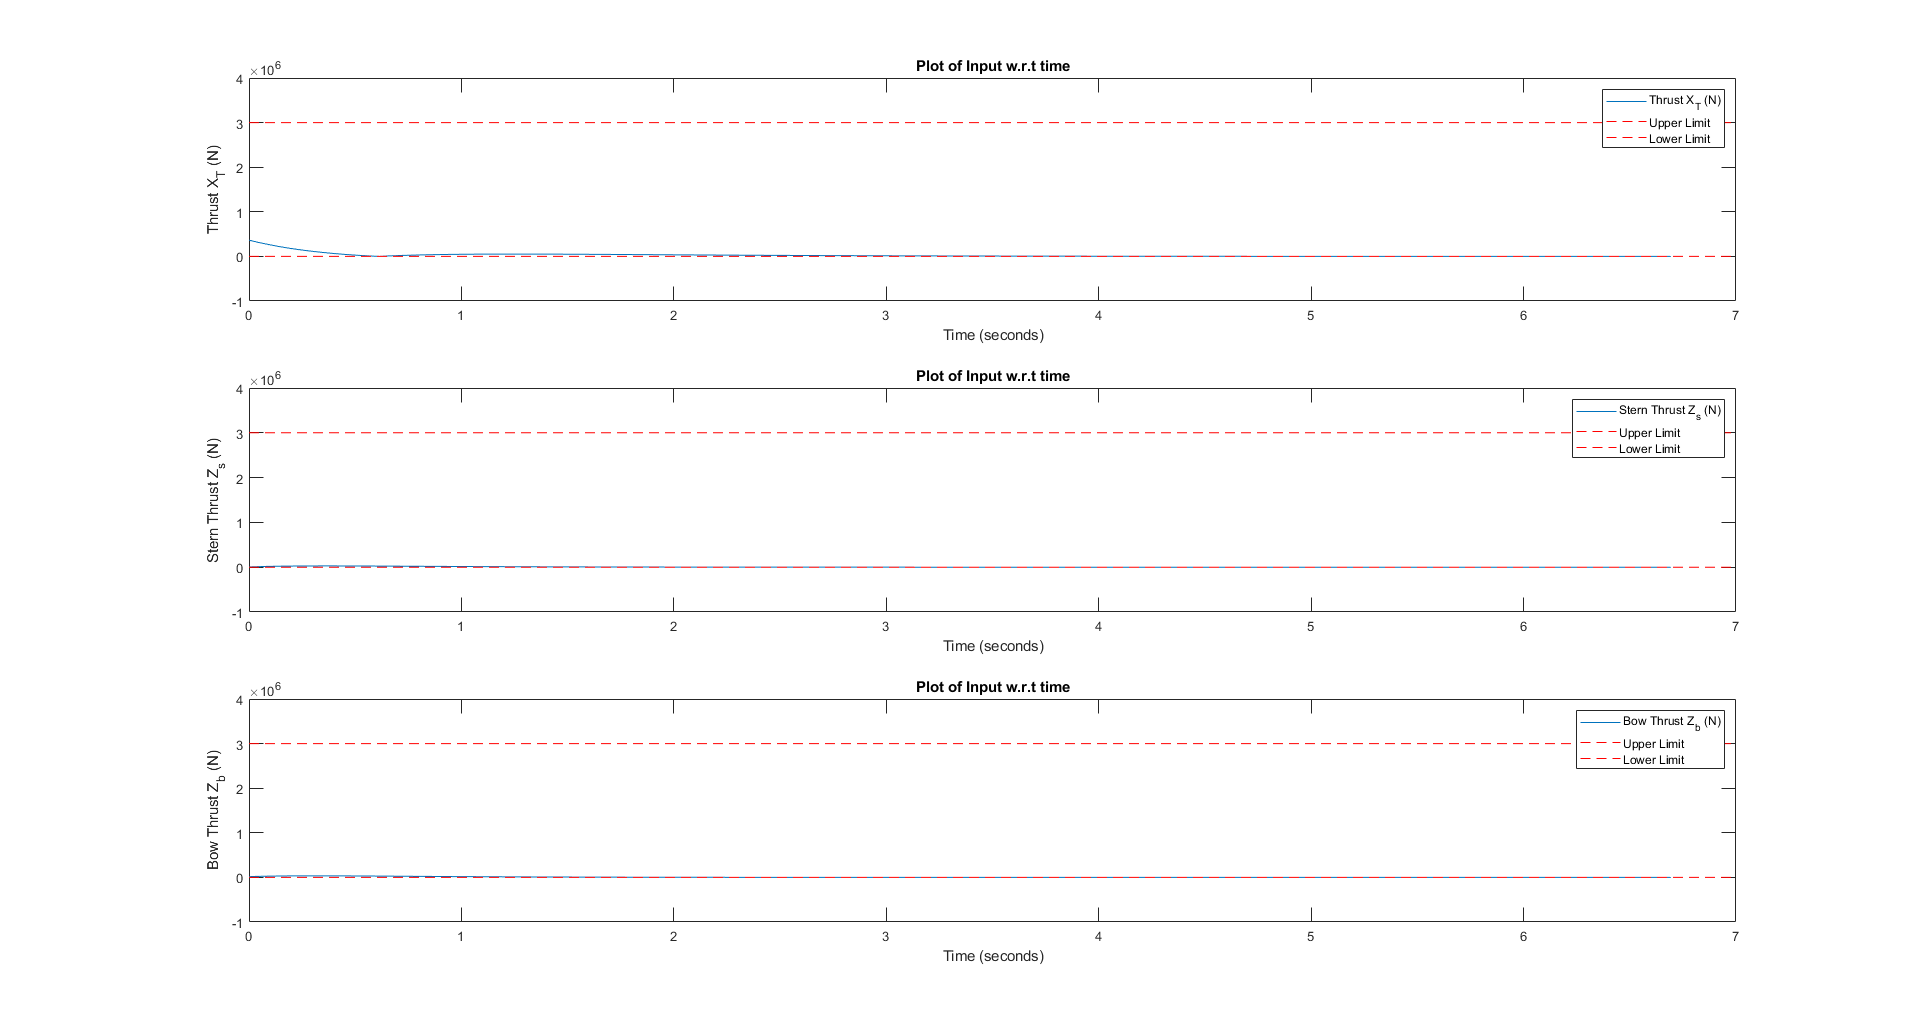


% Plotting Inputs
figure()
subplot(3,1,1)
plot(t1,Thrust1(1,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Thrust X_T (N)')
legend('Thrust X_T (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,2)
plot(t1,Thrust1(2,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Stern Thrust Z_s (N)')
legend('Stern Thrust Z_s (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,3)
plot(t1,Thrust1(3,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Bow Thrust Z_b (N)')
legend('Bow Thrust Z_b (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

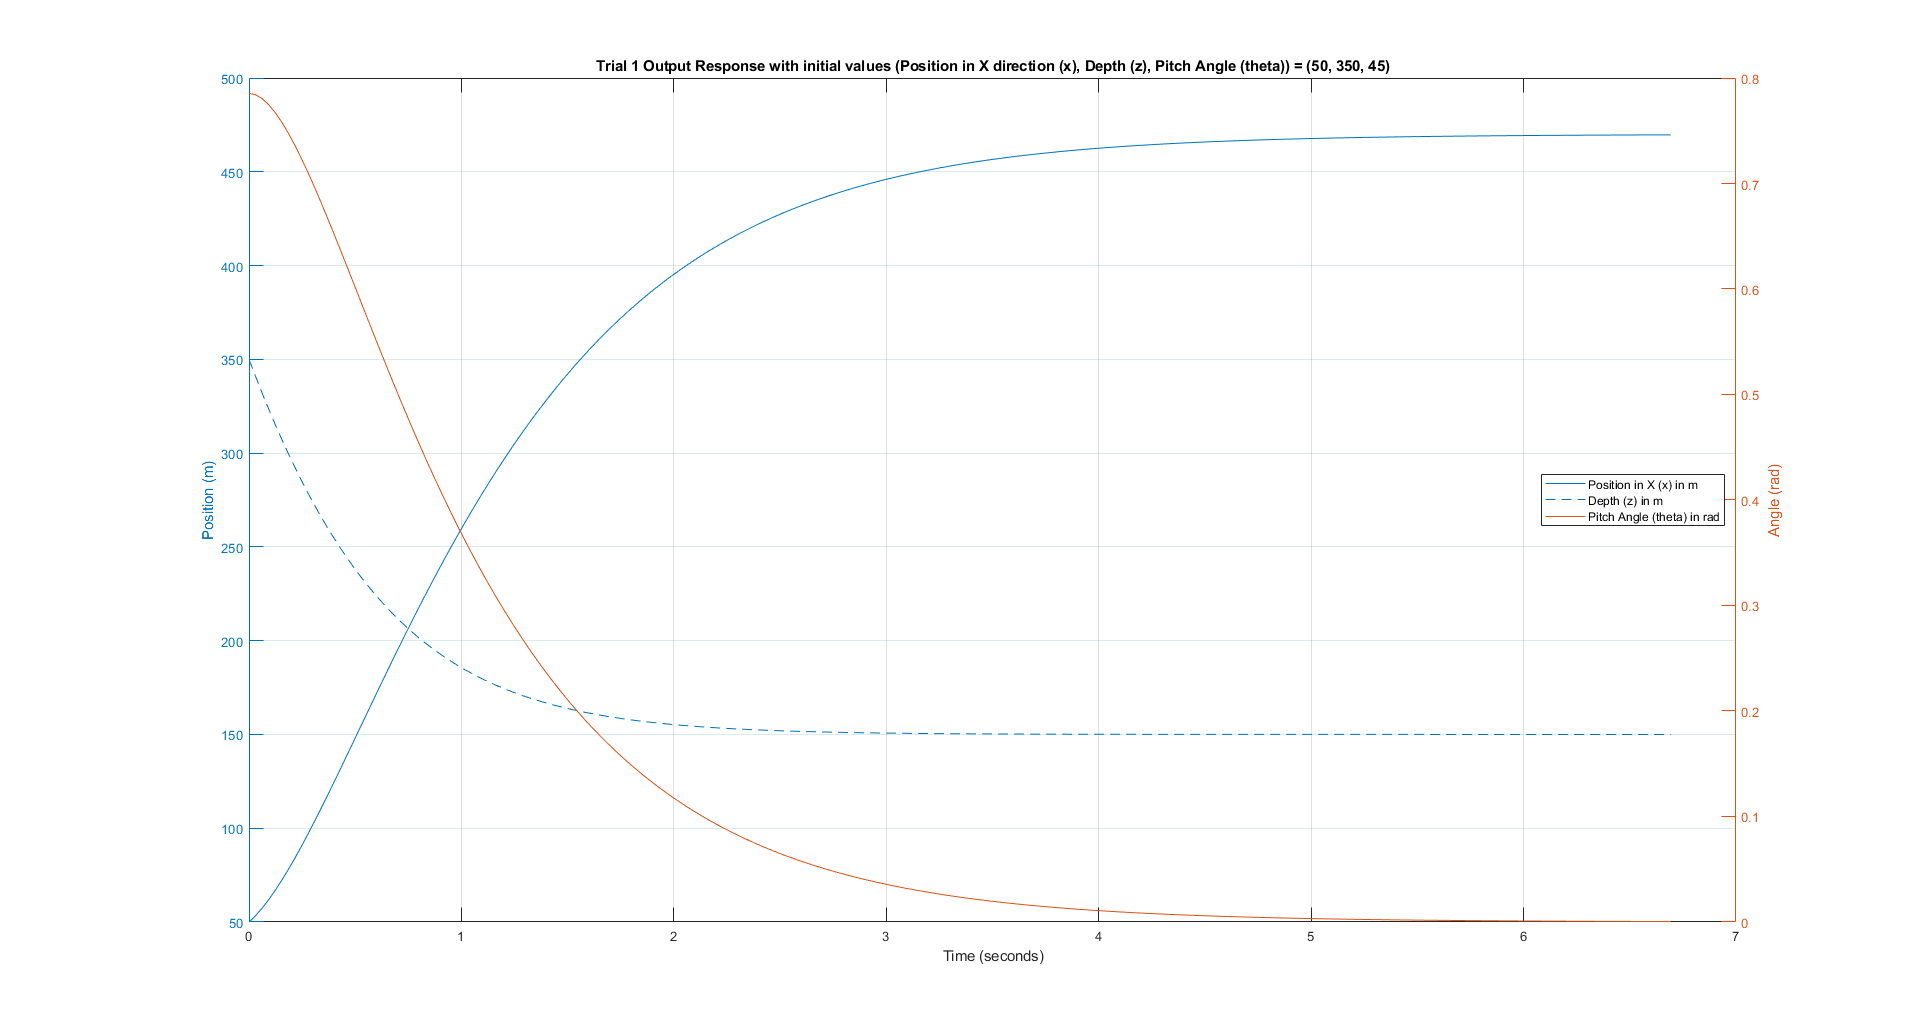


figure()
% Construct the left Y-axes for unit m
yyaxis left
plot(t1,Y1(:,1));
grid on
hold on
plot(t1,Y1(:,2));
title(['Trial 1 Output Response with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Position (m)')

% Construct the right Y-axes for unit rad
yyaxis right
plot(t1,Y1(:,3));
ylabel('Angle (rad)');
h = legend('Position in X (x) in m', 'Depth (z) in m', 'Pitch Angle (theta) in rad');


% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Setting Position of Legend on the Bottom right (southeast)
set(h, 'Location','east');
hold off

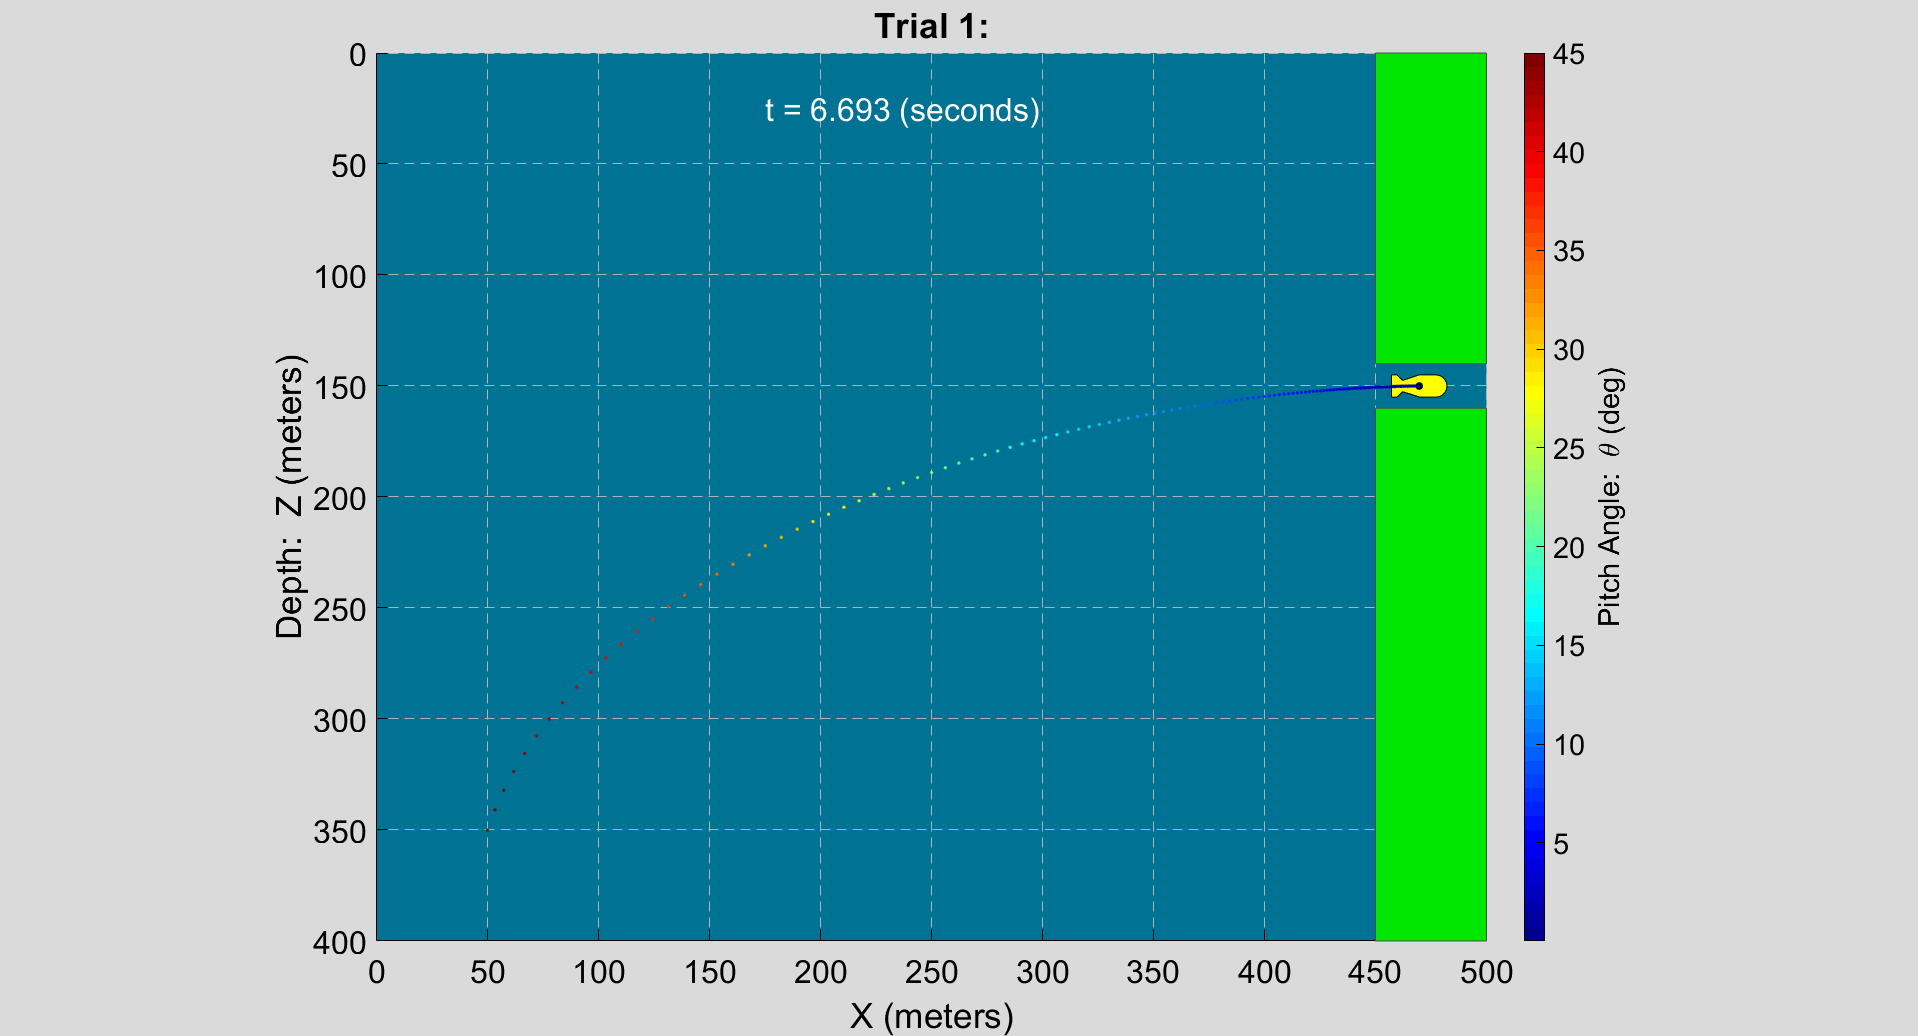


% animate_auv(t,x,z,theta,savemovie);
animate_auv(t1,Y1(:,1),Y1(:,2),Y1(:,3), 0);
title('Trial 1:');

## **Trial 2**

We can further make the response faster and decrease the settling time and time it takes for AUV  to enter the tunnel by increase the real part of some poles. 

Let's start by increasing real part of Poles corresponding to z and $\dot{z}$ from -3 to -9

P2 = [-1.2; -9; -2;-1.2; -9; -2];

disp(' Poles used in Previous Iteration: ');

 Poles used in Previous Iteration: 


disp(vpa(P1));

$$\left(\begin{array}{c} -1.2\\ -3.0\\ -2.0\\ -1.2\\ -3.0\\ -2.0 \end{array}\right)$$

disp(' Poles used in Current Iteration: ');

 Poles used in Current Iteration: 


disp(vpa(P2));

$$\left(\begin{array}{c} -1.2\\ -9.0\\ -2.0\\ -1.2\\ -9.0\\ -2.0 \end{array}\right)$$



K2 = place(A_Numeric,B_Numeric,P2); % proportional gains
A_closed2 = A_Numeric - B_Numeric*K2; % equivalent open-loop A for the closed-loop system
ss_closed2 = ss(A_closed2,B_Numeric,C,D); % still where equivalent U = 0.
[Y2,t2,X2] = initial(ss_closed2, State_Variable_Vector_0);

% Do not forget to return the coordinate system back to normal
Y2(:,1) = Y2(:,1) + 470;
Y2(:,2) = Y2(:,2) + 150;

SimulationStuff12 = lsiminfo(Y2(:,1),t2,'SettlingTimeThreshold',0.05);
SimulationStuff22 = lsiminfo(Y2(:,2),t2,'SettlingTimeThreshold',0.05);
SimulationStuff32 = lsiminfo(Y2(:,3),t2,'SettlingTimeThreshold',0.05);
disp(' ======================= TRIAL 2 ======================== ');

 ======================= TRIAL 2 ======================== 


disp(' ');



% show the settling time for each output: 
disp([' 5% Settling Time for Position in x-direction(x) is: ', ...
    num2str(SimulationStuff12.SettlingTime), 's']);

 5% Settling Time for Position in x-direction(x) is: 3.0561s


disp([' 5% Settling Time for Depth(z) is: ',...
    num2str(SimulationStuff22.SettlingTime), 's']);

 5% Settling Time for Depth(z) is: 1.5322s


disp([' 5% Settling Time for Pitch Angle(theta) is: ',...
    num2str(SimulationStuff32.SettlingTime), 's']);

 5% Settling Time for Pitch Angle(theta) is: 2.5847s


Thrust2 = abs(K2*X2'); % magnitudes of ctrl thrust measurementt at each timestep
worst_control_Thrust_2 = max(max(Thrust2));
fprintf(' Worst Control Thrust is: %6.f N or %.1e N ', worst_control_Thrust_2, worst_control_Thrust_2);

 Worst Control Thrust is: 364021 N or 3.6e+05 N 

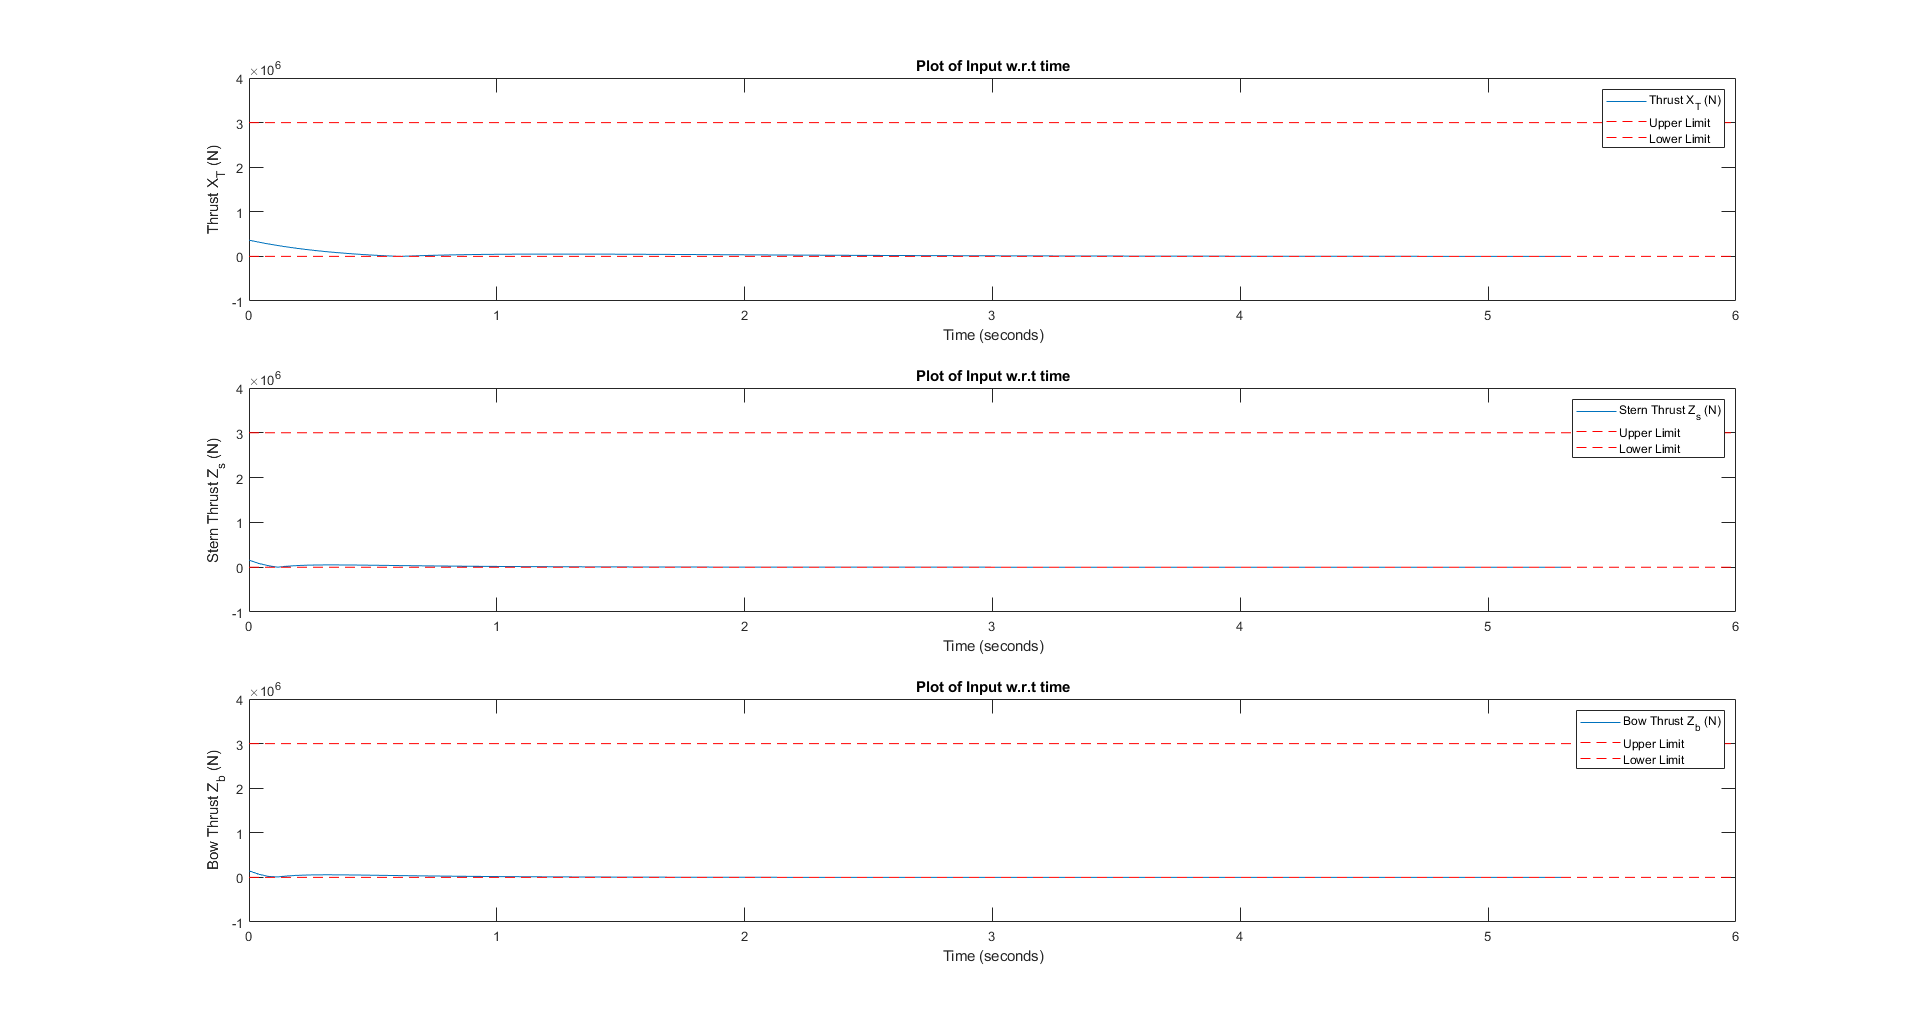


% Plotting Inputs
figure()
subplot(3,1,1)
plot(t2,Thrust2(1,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Thrust X_T (N)')
legend('Thrust X_T (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,2)
plot(t2,Thrust2(2,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Stern Thrust Z_s (N)')
legend('Stern Thrust Z_s (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,3)
plot(t2,Thrust2(3,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Bow Thrust Z_b (N)')
legend('Bow Thrust Z_b (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

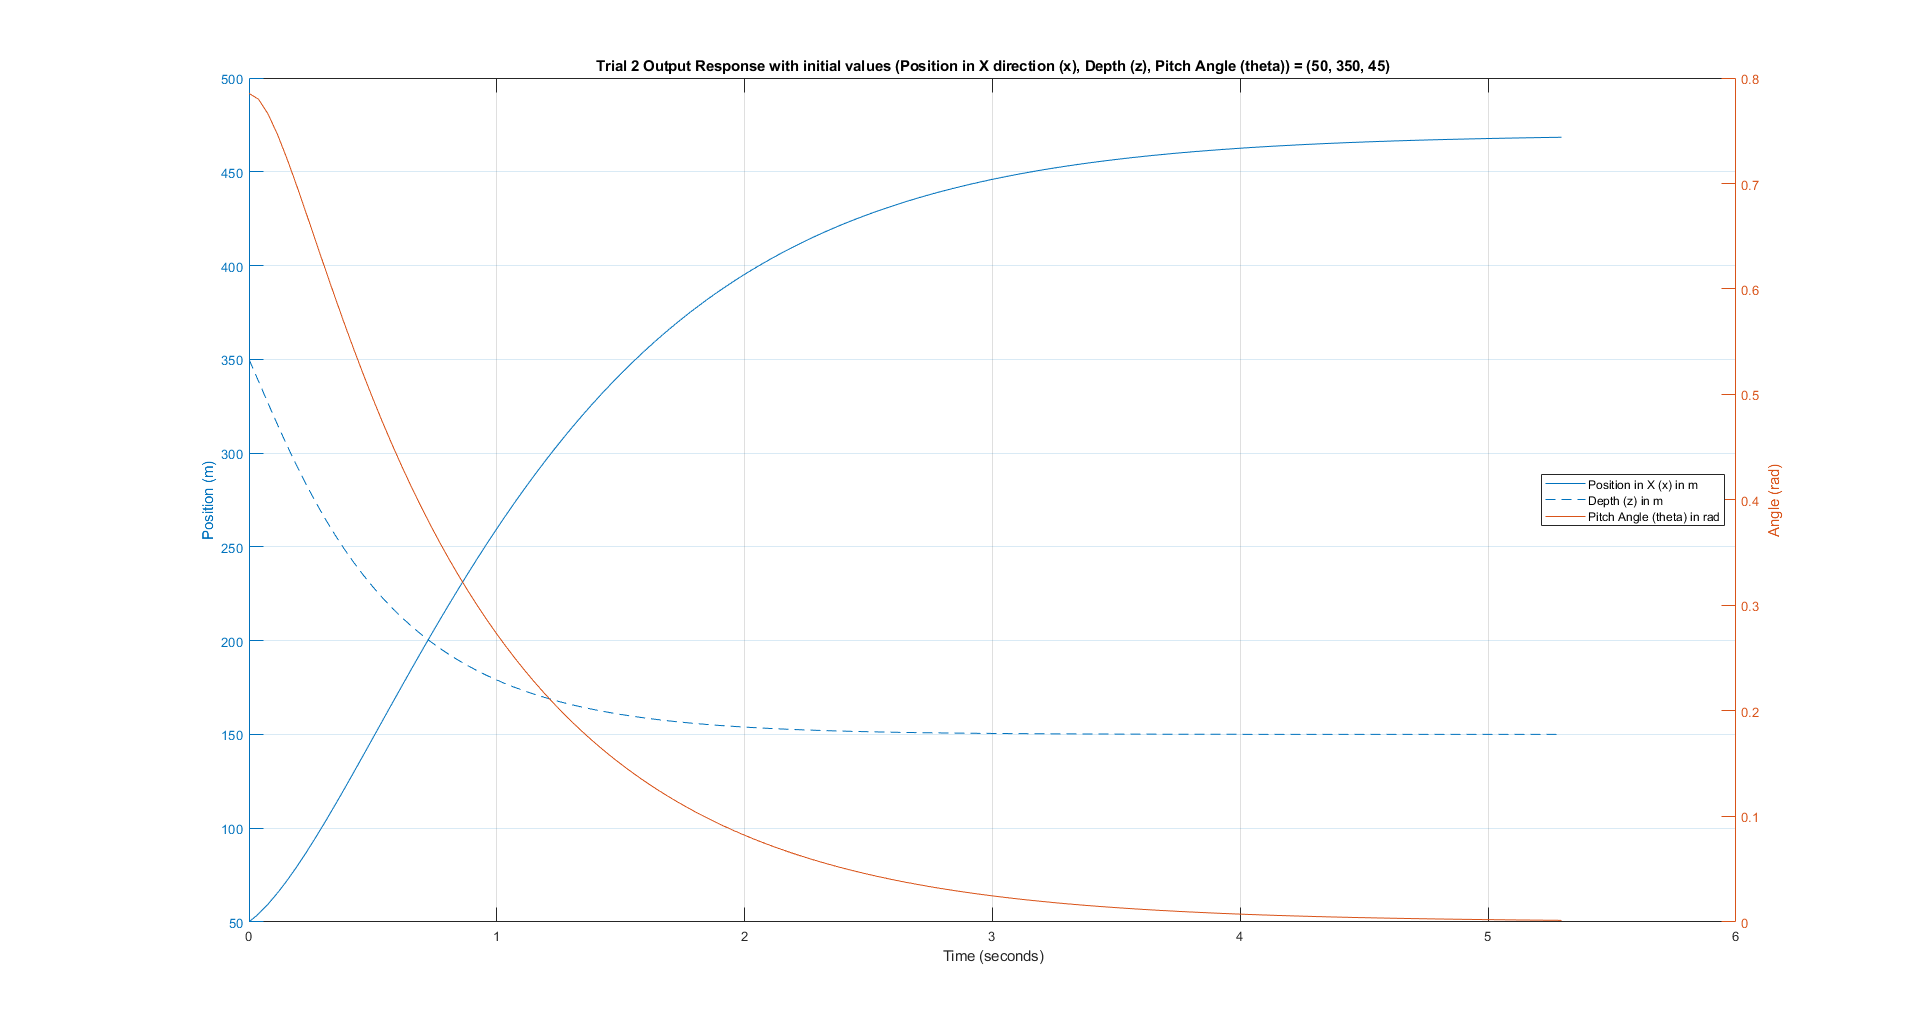


figure()
% Construct the left Y-axes for unit m
yyaxis left
plot(t2,Y2(:,1));
grid on
hold on
plot(t2,Y2(:,2));
title(['Trial 2 Output Response with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Position (m)')

% Construct the right Y-axes for unit rad
yyaxis right
plot(t2,Y2(:,3));
ylabel('Angle (rad)');
h = legend('Position in X (x) in m', 'Depth (z) in m', 'Pitch Angle (theta) in rad');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Setting Position of Legend on the Bottom right (southeast)
set(h, 'Location','east');
hold off


% animate_auv(t,x,z,theta,savemovie);
% savemovie = false;
animate_auv(t2,Y2(:,1),Y2(:,2),Y2(:,3), 'false');

title('Trial 2:');
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);


## **Trial 3**

We were able to decrease settling time for each output response and the time it takes for AUV  to enter the tunnel, but further movement of the Poles at 3 and 6 position did not result in further decrease in time. Also we still have our Max value of thrust at 3.6e+05, so still have room to increase the thrust value without saturating the controller.

Let's try increasing real part of Poles corresponding to x and $\dot{x}$ from -1.2 to -2.75

P3 = [-2.75; -9; -2;-2.75; -9; -2];

disp(' Poles used in Previous Iteration: ');

 Poles used in Previous Iteration: 


disp(vpa(P2));

$$\left(\begin{array}{c} -1.2\\ -9.0\\ -2.0\\ -1.2\\ -9.0\\ -2.0 \end{array}\right)$$

disp(' Poles used in Current Iteration: ');

 Poles used in Current Iteration: 


disp(vpa(P3));

$$\left(\begin{array}{c} -2.75\\ -9.0\\ -2.0\\ -2.75\\ -9.0\\ -2.0 \end{array}\right)$$



K3 = place(A_Numeric,B_Numeric,P3); % proportional gains
A_closed3 = A_Numeric - B_Numeric*K3; % equivalent open-loop A for the closed-loop system
ss_closed3 = ss(A_closed3,B_Numeric,C,D); % still where equivalent U = 0.
[Y3,t3,X3] = initial(ss_closed3, State_Variable_Vector_0);

% Do not forget to return the coordinate system back to normal
Y3(:,1) = Y3(:,1) + 470;
Y3(:,2) = Y3(:,2) + 150;

SimulationStuff13 = lsiminfo(Y3(:,1),t3,'SettlingTimeThreshold',0.05);
SimulationStuff23 = lsiminfo(Y3(:,2),t3,'SettlingTimeThreshold',0.05);
SimulationStuff33 = lsiminfo(Y3(:,3),t3,'SettlingTimeThreshold',0.05);
disp(' ======================= TRIAL 3 ======================== ');

 ======================= TRIAL 3 ======================== 


disp(' ');



% show the settling time for each output: 
disp([' 5% Settling Time for Position in x-direction(x) is: ', ...
    num2str(SimulationStuff13.SettlingTime), 's']);

 5% Settling Time for Position in x-direction(x) is: 1.9856s


disp([' 5% Settling Time for Depth(z) is: ',...
    num2str(SimulationStuff23.SettlingTime), 's']);

 5% Settling Time for Depth(z) is: 1.5219s


disp([' 5% Settling Time for Pitch Angle(theta) is: ',...
    num2str(SimulationStuff33.SettlingTime), 's']);

 5% Settling Time for Pitch Angle(theta) is: 1.2211s


Thrust3 = abs(K3*X3'); % magnitudes of ctrl thrust measurementt at each timestep
worst_control_Thrust_3 = max(max(Thrust3));
fprintf(' Worst Control Thrust is: %6.f N or %.1e N ', worst_control_Thrust_3, worst_control_Thrust_3);

 Worst Control Thrust is: 955258 N or 9.6e+05 N 

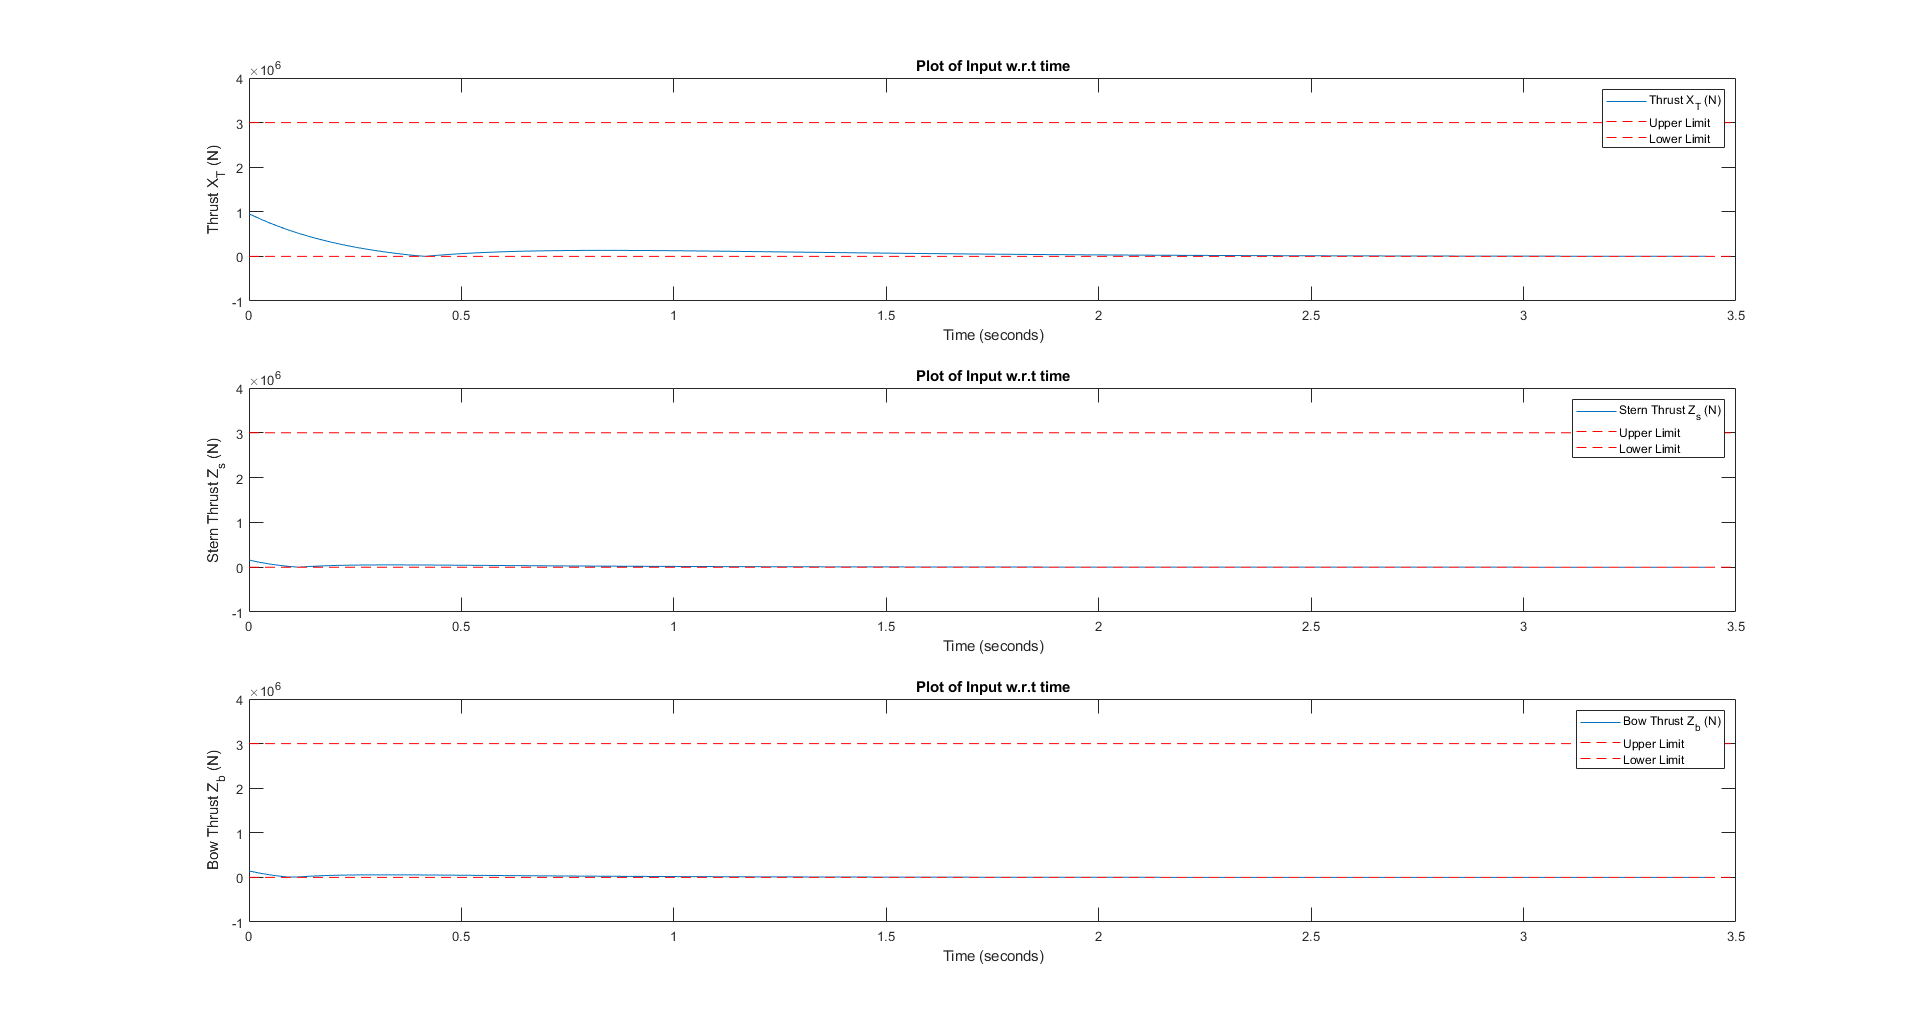


% Plotting Inputs
figure()
subplot(3,1,1)
plot(t3,Thrust3(1,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Thrust X_T (N)')
legend('Thrust X_T (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,2)
plot(t3,Thrust3(2,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Stern Thrust Z_s (N)')
legend('Stern Thrust Z_s (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,3)
plot(t3,Thrust3(3,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Bow Thrust Z_b (N)')
legend('Bow Thrust Z_b (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

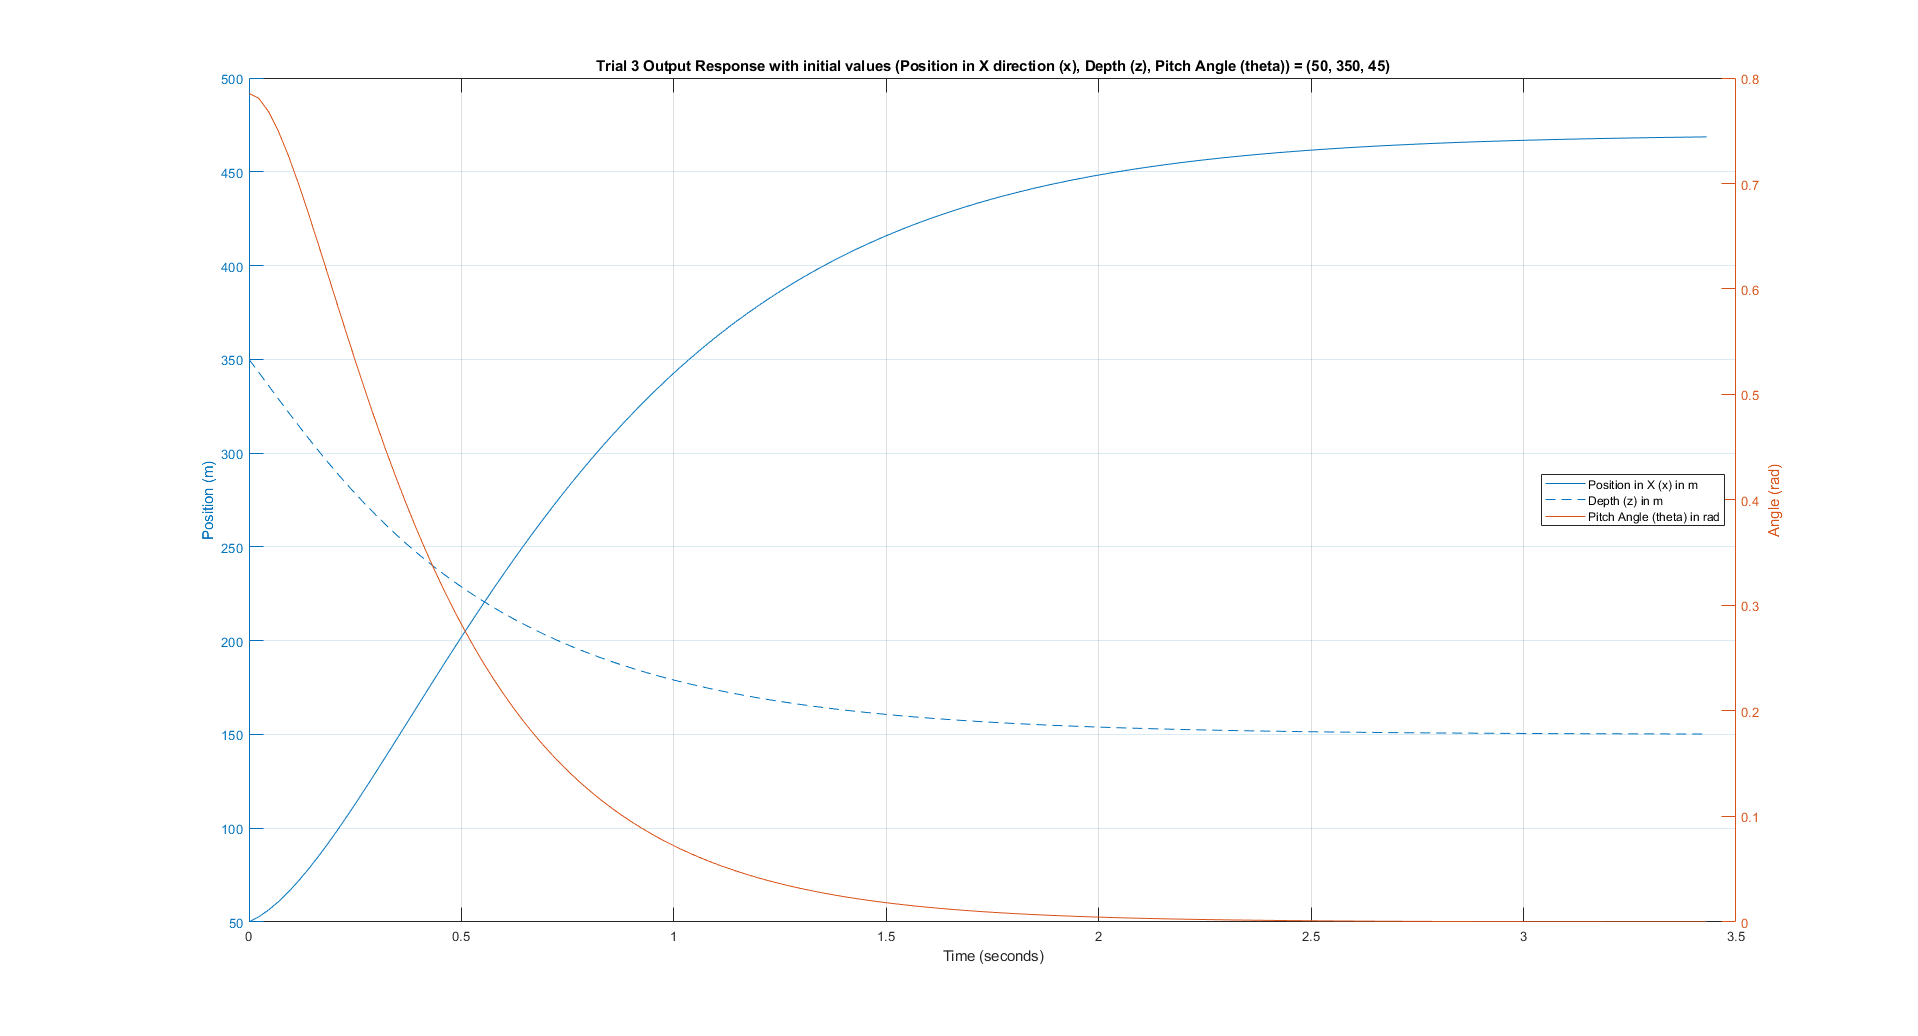


figure()
% Construct the left Y-axes for unit m
yyaxis left
plot(t3,Y3(:,1));
grid on
hold on
plot(t3,Y3(:,2));
title(['Trial 3 Output Response with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Position (m)')

% Construct the right Y-axes for unit rad
yyaxis right
plot(t3,Y3(:,3));
ylabel('Angle (rad)');
h = legend('Position in X (x) in m', 'Depth (z) in m', 'Pitch Angle (theta) in rad');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Setting Position of Legend on the Bottom right (southeast)
set(h, 'Location','east');
hold off

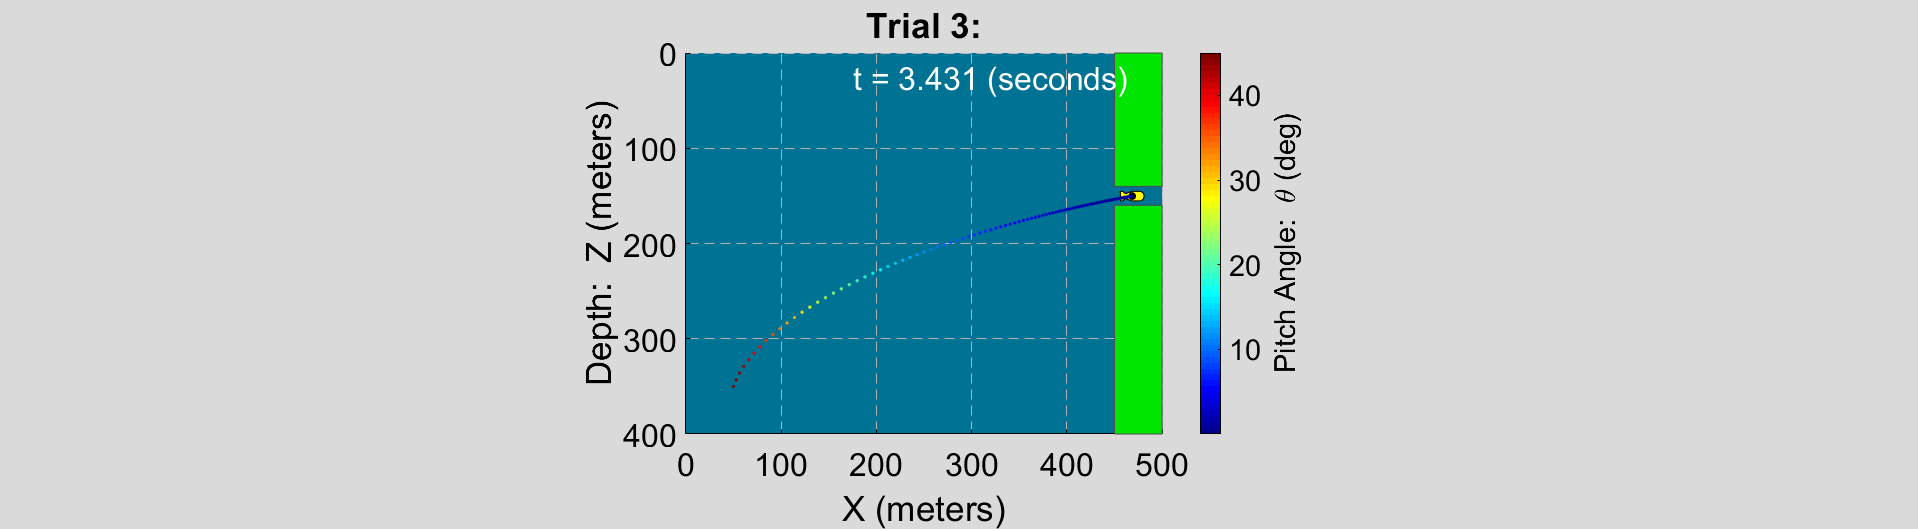


% animate_auv(t,x,z,theta,savemovie);
animate_auv(t3,Y3(:,1),Y3(:,2),Y3(:,3), 0);
title('Trial 3:');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## **Trial 4**

Our Max Value thrust increased from 3.6e+05 to 9.6e+05 whcih still have has room to increase without saturation of the controller. and our settling time value of x and $\theta$ also decreased respective with time for AUV entrance going below 3.5 sec. Further increase in the Poles 1 and 4 would result in crashing of the vehicle. Thus,

Let's try increasing real part of Poles corresponding to $\theta$ and $\theta^˙$ from -2 to -4.7 to further increase our Max Thrust and decrease the time for AUV entrance

P4 = [-2.75; -9; -4.7;-2.75; -9; -4.7];

disp(' Poles used in Previous Iteration: ');

 Poles used in Previous Iteration: 


disp(vpa(P3));

$$\left(\begin{array}{c} -2.75\\ -9.0\\ -2.0\\ -2.75\\ -9.0\\ -2.0 \end{array}\right)$$

disp(' Poles used in Current Iteration: ');

 Poles used in Current Iteration: 


disp(vpa(P4));

$$\left(\begin{array}{c} -2.75\\ -9.0\\ -4.7\\ -2.75\\ -9.0\\ -4.7 \end{array}\right)$$



K4 = place(A_Numeric,B_Numeric,P4); % proportional gains
A_closed4 = A_Numeric - B_Numeric*K4; % equivalent open-loop A for the closed-loop system
ss_closed4 = ss(A_closed4,B_Numeric,C,D); % still where equivalent U = 0.
[Y4,t4,X4] = initial(ss_closed4, State_Variable_Vector_0);

% Do not forget to return the coordinate system back to normal
Y4(:,1) = Y4(:,1) + 470;
Y4(:,2) = Y4(:,2) + 150;

SimulationStuff14 = lsiminfo(Y4(:,1),t4,'SettlingTimeThreshold',0.05);
SimulationStuff24 = lsiminfo(Y4(:,2),t4,'SettlingTimeThreshold',0.05);
SimulationStuff34 = lsiminfo(Y4(:,3),t4,'SettlingTimeThreshold',0.05);
disp(' ======================= TRIAL 4 ======================== ');

 ======================= TRIAL 4 ======================== 


disp(' ');



% show the settling time for each output: 
disp([' 5% Settling Time for Position in x-direction(x) is: ', ...
    num2str(SimulationStuff14.SettlingTime), 's']);

 5% Settling Time for Position in x-direction(x) is: 1.3512s


disp([' 5% Settling Time for Depth(z) is: ',...
    num2str(SimulationStuff24.SettlingTime), 's']);

 5% Settling Time for Depth(z) is: 0.75208s


disp([' 5% Settling Time for Pitch Angle(theta) is: ',...
    num2str(SimulationStuff34.SettlingTime), 's']);

 5% Settling Time for Pitch Angle(theta) is: 1.2064s


Thrust4 = abs(K4*X4'); % magnitudes of ctrl thrust measurementt at each timestep
worst_control_Thrust_4 = max(max(Thrust4));
fprintf(' Worst Control Thrust is: %6.f N or %.1e N ', worst_control_Thrust_4, worst_control_Thrust_4);

 Worst Control Thrust is: 2423557 N or 2.4e+06 N 

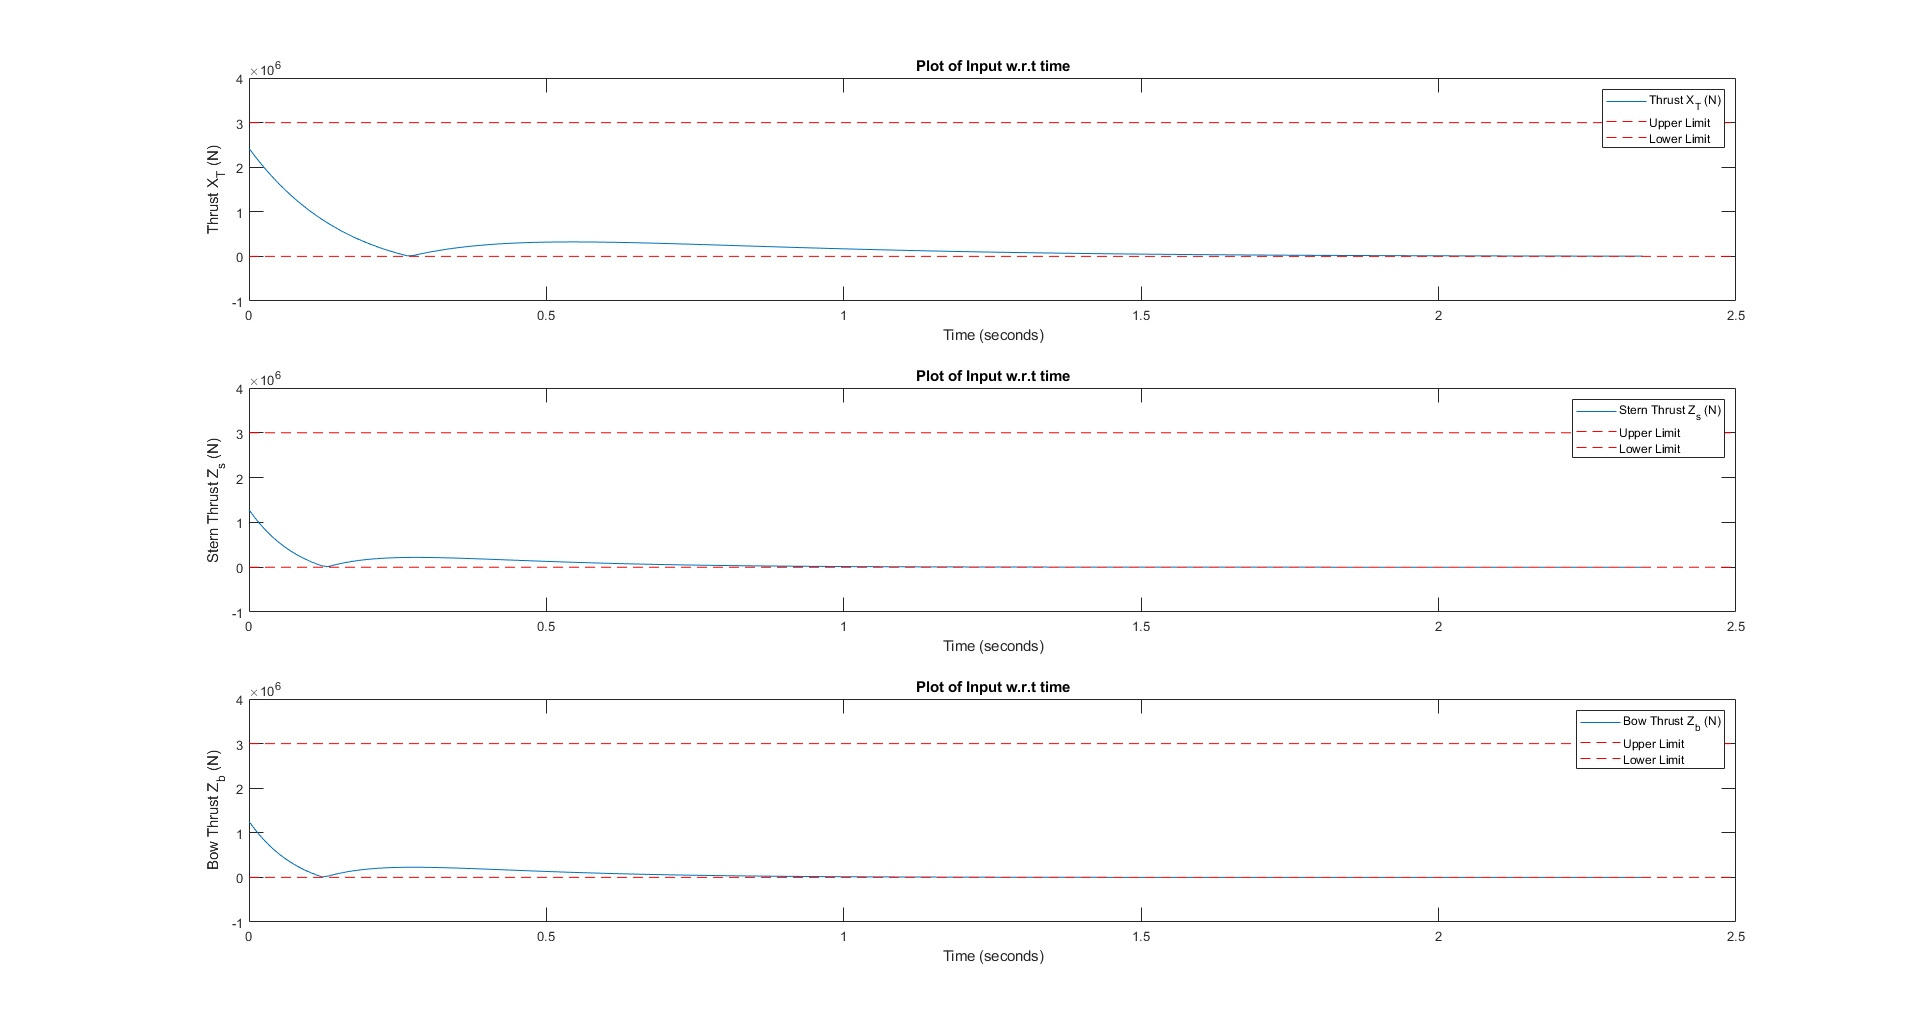


% Plotting Inputs
figure()
subplot(3,1,1)
plot(t4,Thrust4(1,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Thrust X_T (N)')
legend('Thrust X_T (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,2)
plot(t4,Thrust4(2,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Stern Thrust Z_s (N)')
legend('Stern Thrust Z_s (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,3)
plot(t4,Thrust4(3,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Bow Thrust Z_b (N)')
legend('Bow Thrust Z_b (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

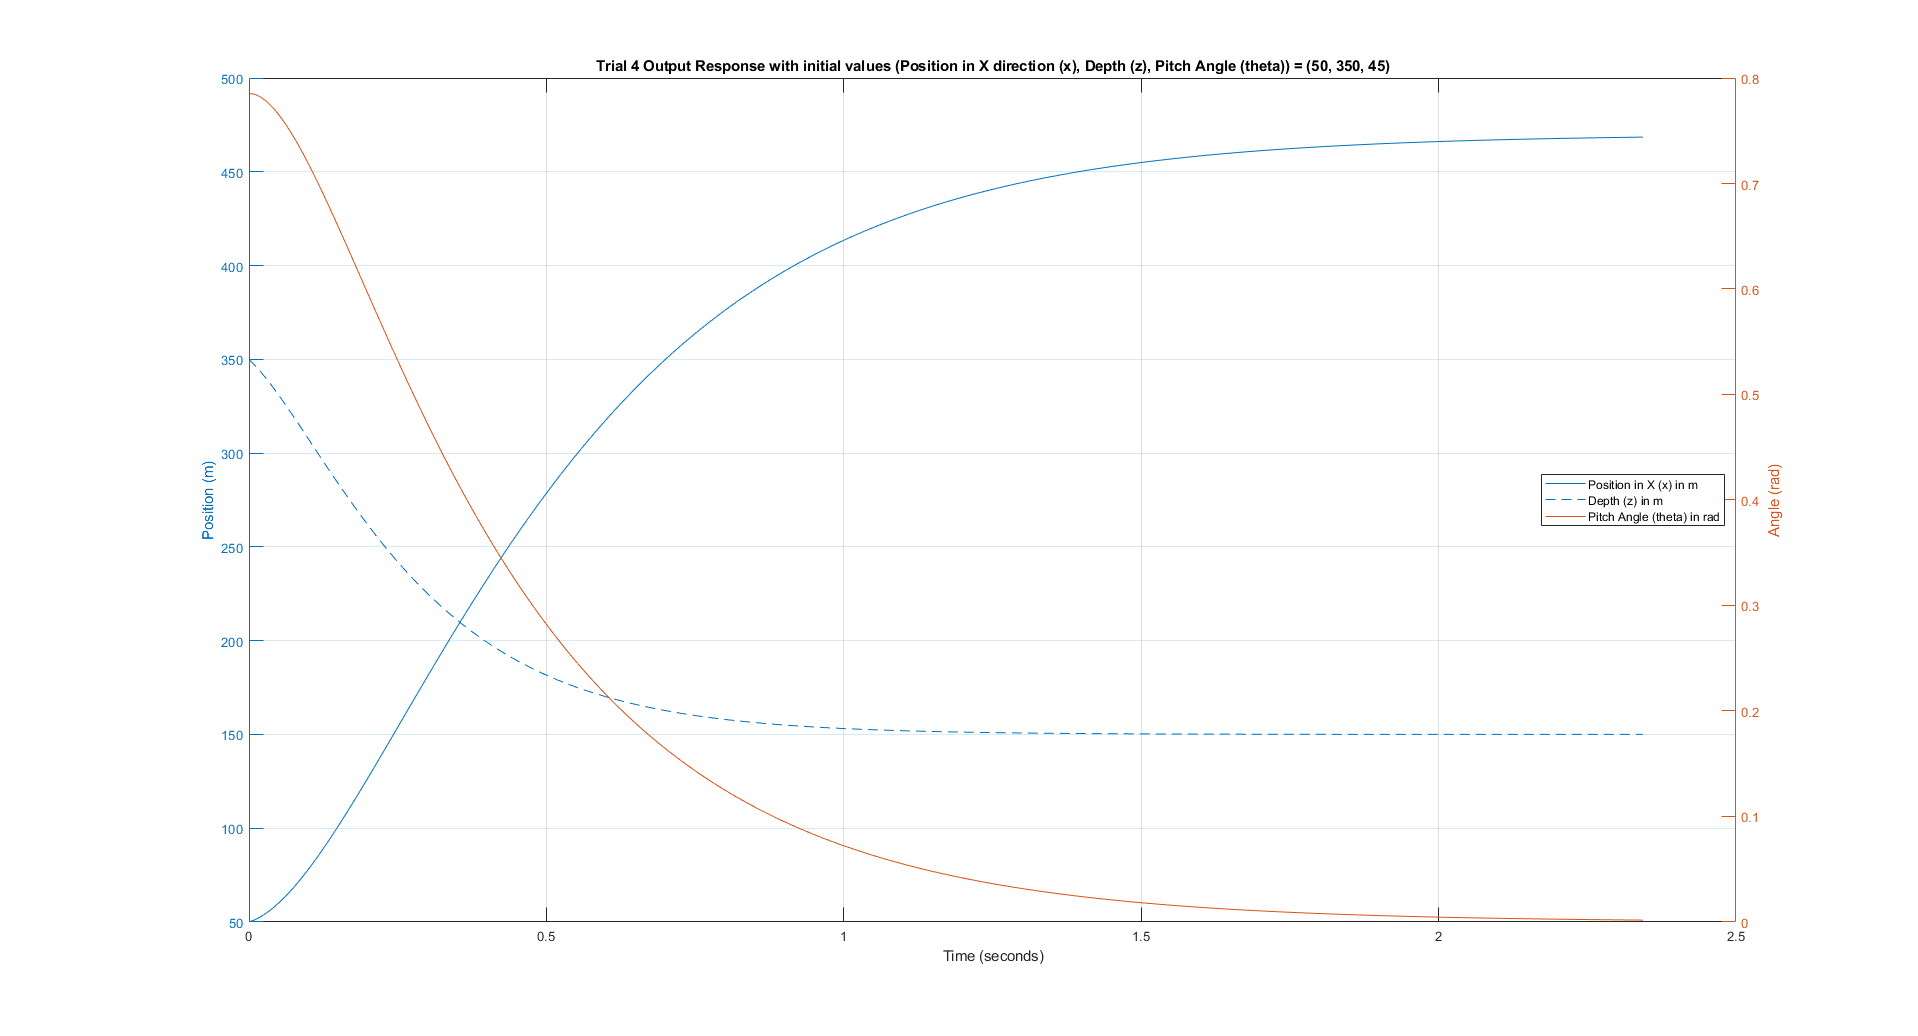


figure()
% Construct the left Y-axes for unit m
yyaxis left
plot(t4,Y4(:,1));
grid on
hold on
plot(t4,Y4(:,2));
title(['Trial 4 Output Response with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Position (m)')

% Construct the right Y-axes for unit rad
yyaxis right
plot(t4,Y4(:,3));
ylabel('Angle (rad)');
h = legend('Position in X (x) in m', 'Depth (z) in m', 'Pitch Angle (theta) in rad');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Setting Position of Legend on the Bottom right (southeast)
set(h, 'Location','east');
hold off

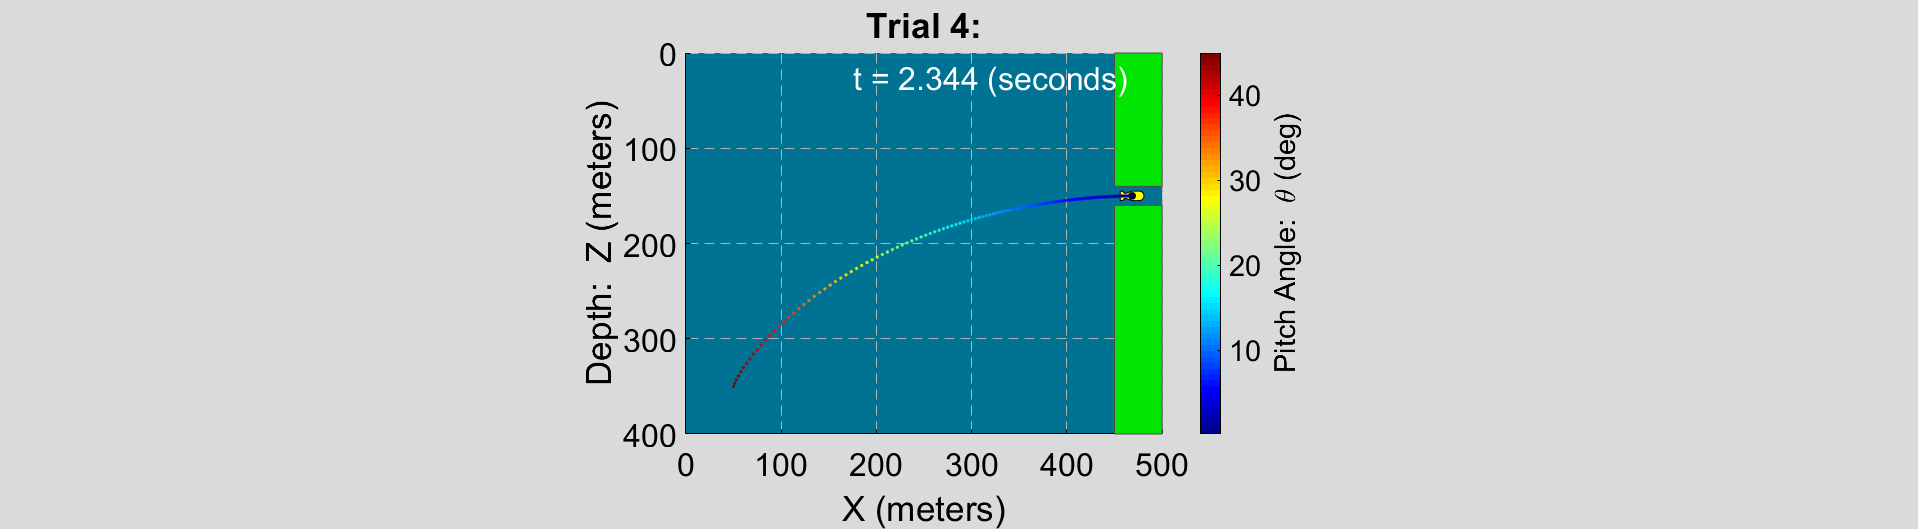


% animate_auv(t,x,z,theta,savemovie);
animate_auv(t4,Y4(:,1),Y4(:,2),Y4(:,3), 0);
title('Trial 4:');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## **Trial 5**

Our Max Value thrust increased from 9.6e+05 to 2.4e+06 whcih is very close to saturation of the controller. and our settling time value of x, z and $\theta$ also decreased respective with time for AUV entrance going below 2.5 sec. Further increase in the Poles 3 and 6 would result in increase of time for AUV to enter the tunnel eventhough there is further decrease in settling time and increase in Max Thrust. Thus,

We know, that further increase in real part of poles corresponding to  $x$, z, $\dot{x}$ and $\dot{z}$, does not increase the Max Thrust by a large margin but still helps decreasing the settling time and time for AUV to enter tunnel.

Let's try increasing real part of Poles corresponding to $x$ and $\dot{x}$ from -2.75 to -3.3 and z and $\dot{z}$ from -12 to -18

P5 = [-3.3; -18; -4.7;-3.3; -18; -4.7];

disp(' Poles used in Previous Iteration: ');

 Poles used in Previous Iteration: 


disp(vpa(P4));

$$\left(\begin{array}{c} -2.75\\ -9.0\\ -4.7\\ -2.75\\ -9.0\\ -4.7 \end{array}\right)$$

disp(' Poles used in Current Iteration: ');

 Poles used in Current Iteration: 


disp(vpa(P5));

$$\left(\begin{array}{c} -3.3\\ -18.0\\ -4.7\\ -3.3\\ -18.0\\ -4.7 \end{array}\right)$$



K5 = place(A_Numeric,B_Numeric,P5); % proportional gains
A_closed5 = A_Numeric - B_Numeric*K5; % equivalent open-loop A for the closed-loop system
ss_closed5 = ss(A_closed5,B_Numeric,C,D); % still where equivalent U = 0.
[Y5,t5,X5] = initial(ss_closed5, State_Variable_Vector_0);

% Do not forget to return the coordinate system back to normal
Y5(:,1) = Y5(:,1) + 470;
Y5(:,2) = Y5(:,2) + 150;

SimulationStuff15 = lsiminfo(Y5(:,1),t5,'SettlingTimeThreshold',0.05);
SimulationStuff25 = lsiminfo(Y5(:,2),t5,'SettlingTimeThreshold',0.05);
SimulationStuff35 = lsiminfo(Y5(:,3),t5,'SettlingTimeThreshold',0.05);
disp(' ======================= TRIAL 5 ======================== ');

 ======================= TRIAL 5 ======================== 


disp(' ');



% show the settling time for each output: 
disp([' 5% Settling Time for Position in x-direction(x) is: ', ...
    num2str(SimulationStuff15.SettlingTime), 's']);

 5% Settling Time for Position in x-direction(x) is: 1.1996s


disp([' 5% Settling Time for Depth(z) is: ',...
    num2str(SimulationStuff25.SettlingTime), 's']);

 5% Settling Time for Depth(z) is: 0.683s


disp([' 5% Settling Time for Pitch Angle(theta) is: ',...
    num2str(SimulationStuff35.SettlingTime), 's']);

 5% Settling Time for Pitch Angle(theta) is: 0.9619s


Thrust5 = abs(K5*X5'); % magnitudes of ctrl thrust measurementt at each timestep
worst_control_Thrust_5 = max(max(Thrust5));
fprintf(' Worst Control Thrust is: %6.f N or %.1e N ', worst_control_Thrust_5, worst_control_Thrust_5);

 Worst Control Thrust is: 2954845 N or 3.0e+06 N 

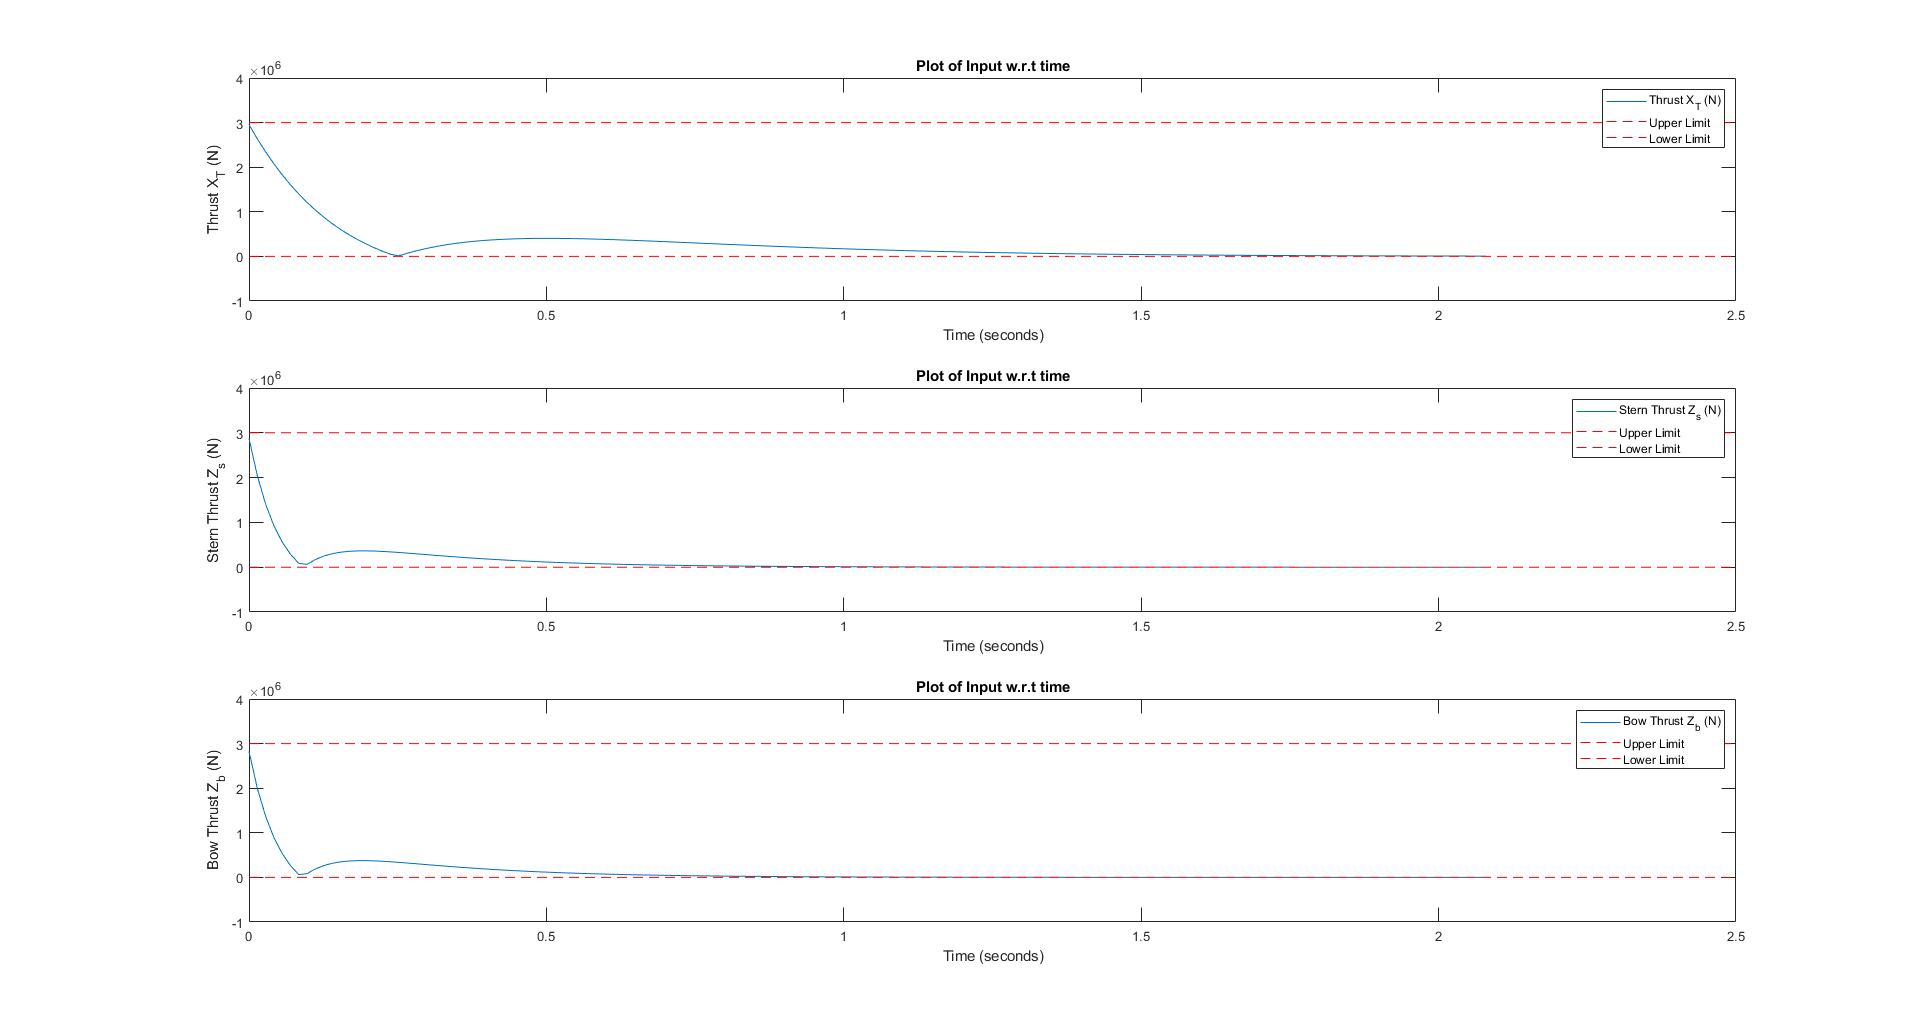


% Plotting Inputs
figure()
subplot(3,1,1)
plot(t5,Thrust5(1,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Thrust X_T (N)')
legend('Thrust X_T (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,2)
plot(t5,Thrust5(2,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Stern Thrust Z_s (N)')
legend('Stern Thrust Z_s (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

subplot(3,1,3)
plot(t5,Thrust5(3,:));
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,0);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Bow Thrust Z_b (N)')
legend('Bow Thrust Z_b (N)','Upper Limit','Lower Limit');
ylim([-1e6 4e6]);

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

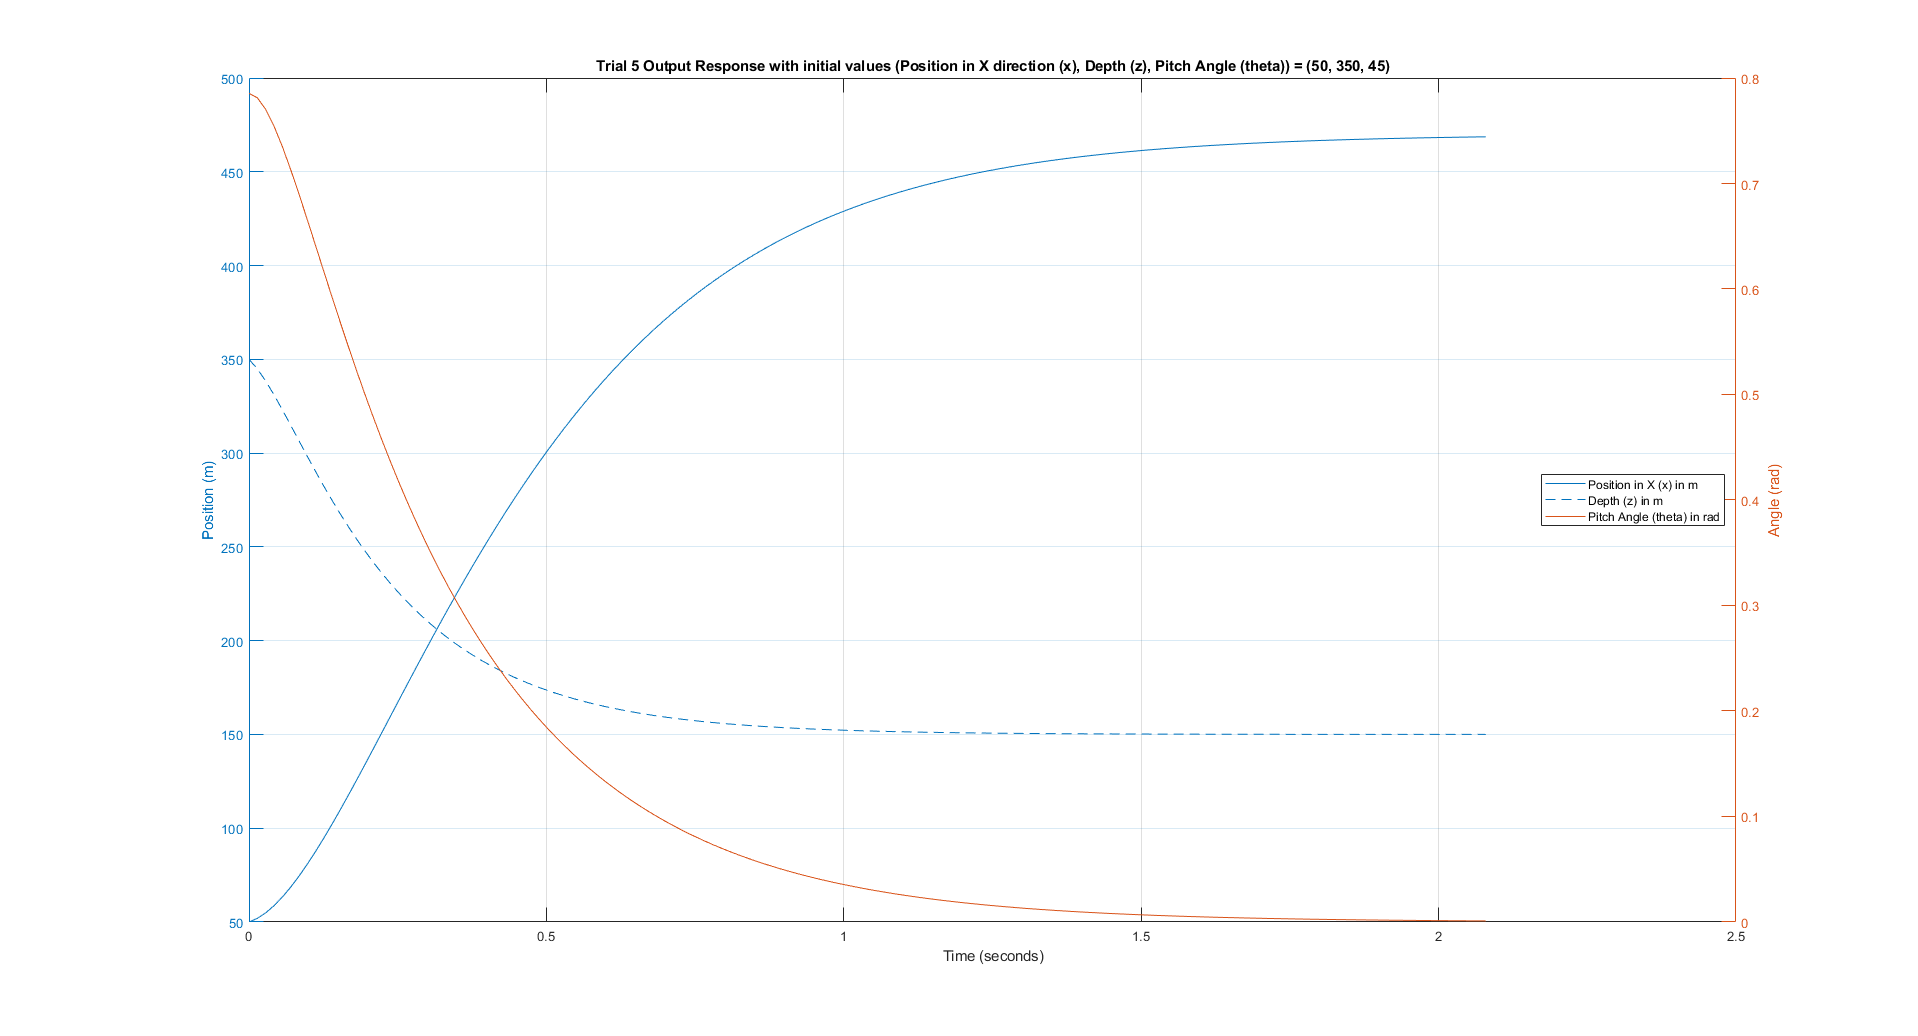


figure()
% Construct the left Y-axes for unit m
yyaxis left
plot(t5,Y5(:,1));
grid on
hold on
plot(t5,Y5(:,2));
title(['Trial 5 Output Response with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Position (m)')

% Construct the right Y-axes for unit rad
yyaxis right
plot(t5,Y5(:,3));
ylabel('Angle (rad)');
h = legend('Position in X (x) in m', 'Depth (z) in m', 'Pitch Angle (theta) in rad');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Setting Position of Legend on the Bottom right (southeast)
set(h, 'Location','east');
hold off

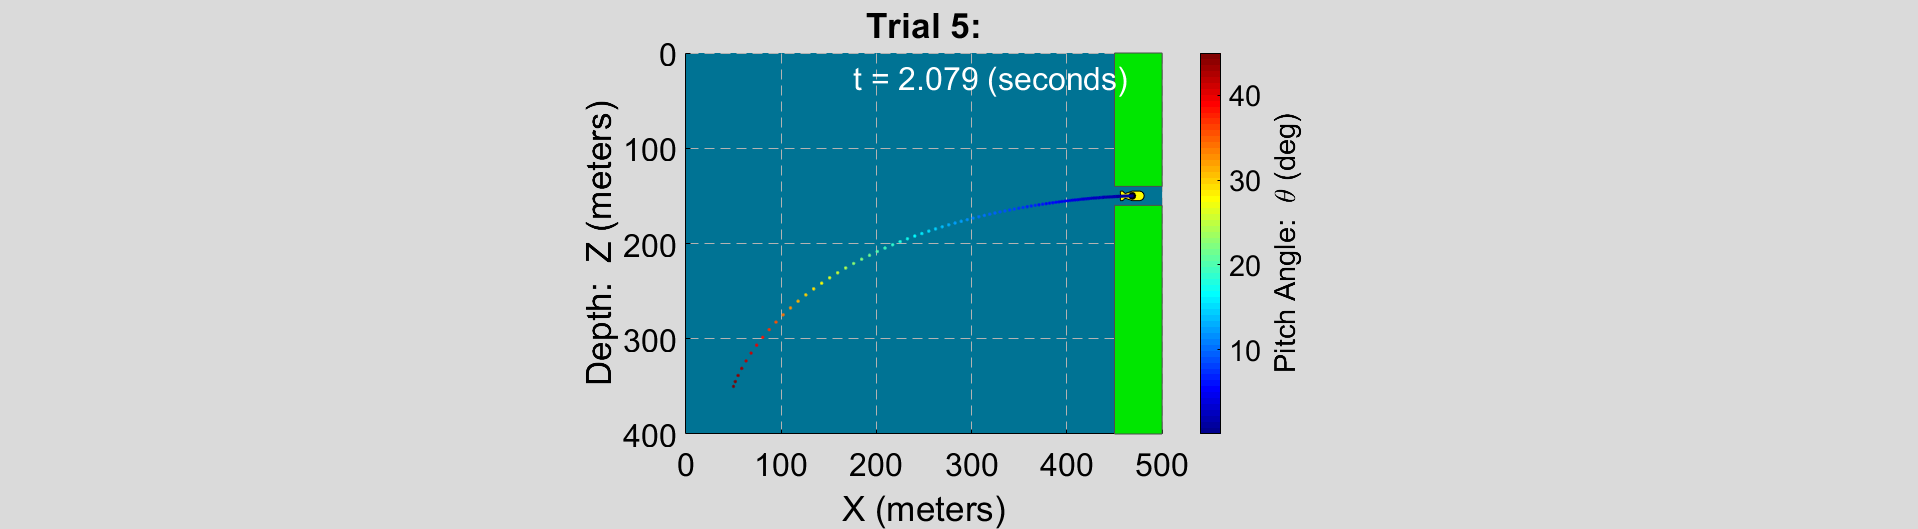


% animate_auv(t,x,z,theta,savemovie);
animate_auv(t5,Y5(:,1),Y5(:,2),Y5(:,3), 0);
title('Trial 5:');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

# Final Design Plot

Final_Feedback_Gain_Matrix = K5;% display the finalized feedback gains
disp(' Final Feedback gain Matrix is: ');

 Final Feedback gain Matrix is: 


disp(Final_Feedback_Gain_Matrix);

   1.0e+04 *

    0.4030         0         0    0.7995         0         0
         0    0.6026    0.1127         0    2.3405    0.4649
         0    0.5991   -0.1538         0    2.3131   -0.3150



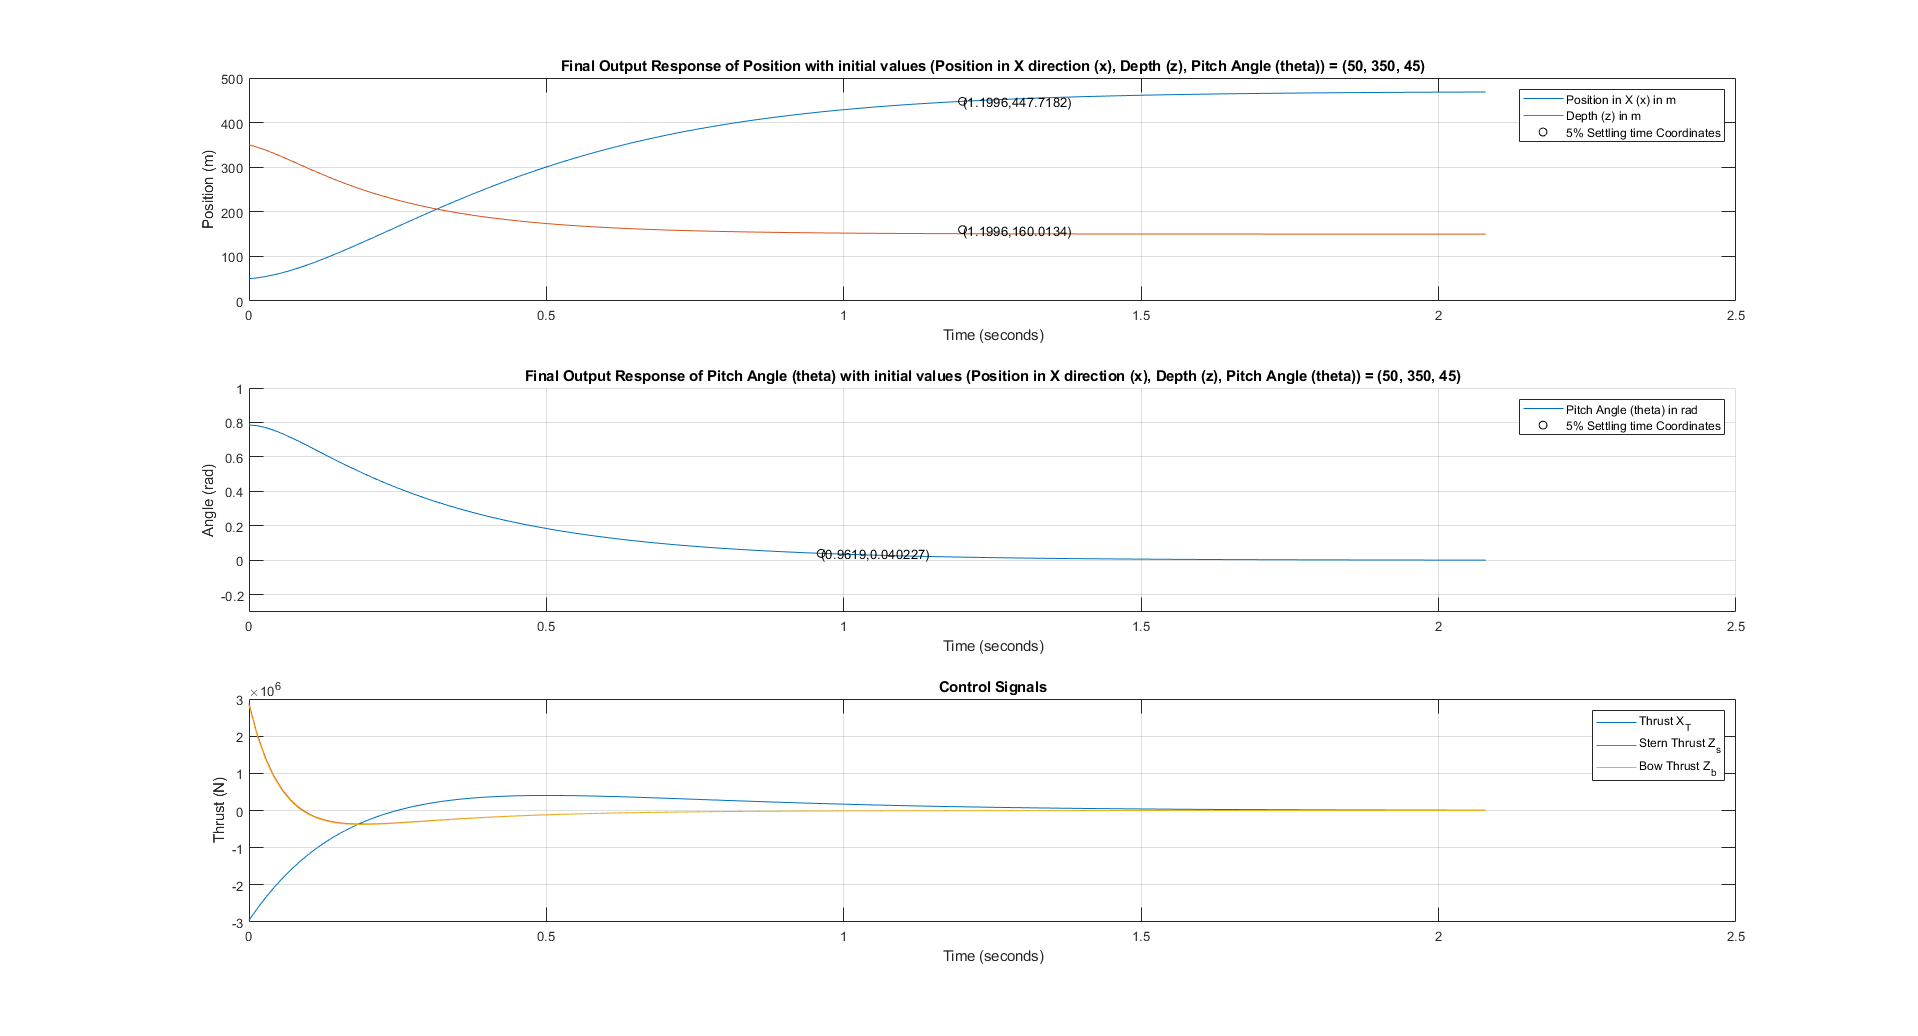


X_at_SettlingTime_Final_Design = interp1(t5(:,1),Y5(:,1),SimulationStuff15.SettlingTime);
Z_at_SettlingTime_Final_Design = interp1(t5(:,1),Y5(:,2),SimulationStuff25.SettlingTime);
Theta_at_SettlingTime_Final_Design = interp1(t5(:,1),Y5(:,3),SimulationStuff35.SettlingTime);


figure()
% Construct the 1st plot of just Positions in m
subplot(3,1,1)
plot(t5,Y5(:,1));
grid on
hold on
plot(t5,Y5(:,2));
title(['Final Output Response of Position with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Position (m)')

plot(SimulationStuff15.SettlingTime, X_at_SettlingTime_Final_Design,'kO');
text(SimulationStuff15.SettlingTime, X_at_SettlingTime_Final_Design,['(' num2str(SimulationStuff15.SettlingTime) ',' num2str(X_at_SettlingTime_Final_Design) ')']);

plot(SimulationStuff15.SettlingTime, Z_at_SettlingTime_Final_Design,'kO');
text(SimulationStuff15.SettlingTime, Z_at_SettlingTime_Final_Design,['(' num2str(SimulationStuff15.SettlingTime) ',' num2str(Z_at_SettlingTime_Final_Design) ')']);
legend('Position in X (x) in m', 'Depth (z) in m','5% Settling time Coordinates');
xlim([0 2.2]);
hold off

% Construct the 2nd Plot of just Pitch Angle in rad
subplot(3,1,2)
hold on
plot(t5,Y5(:,3));
grid on
title(['Final Output Response of Pitch Angle (theta) with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Angle (rad)');

plot(SimulationStuff35.SettlingTime, Theta_at_SettlingTime_Final_Design,'kO');
text(SimulationStuff35.SettlingTime, Theta_at_SettlingTime_Final_Design,['(' num2str(SimulationStuff35.SettlingTime) ',' num2str(Theta_at_SettlingTime_Final_Design) ')']);
legend('Pitch Angle (theta) in rad','5% Settling time Coordinates');
ylim([-0.3 1]);
xlim([0 2.2]);
hold off

% Setting Position of Legend on the Bottom right (southeast)
% set(h, 'Location','east');
% hold off

CtrlThrust = K5*X5'; % inputs U

% Plotting the Control Signals
subplot(3, 1, 3)
plot(t5, CtrlThrust(1,:))
hold on
plot(t5, CtrlThrust(2,:))
plot(t5, CtrlThrust(3,:))
hold off
grid on
legend('Thrust X_T', 'Stern Thrust Z_s', 'Bow Thrust Z_b');
xlabel('Time (seconds)');
ylabel('Thrust (N)');
title('Control Signals');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

xlim([0 2.2]);

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);